## Code for weight estimation of multiple-truck events using MP NOR-BWIM approach

The purpose of this code is to perform two steps: 1) calibration using single truck passages and then 2) weight estimation in multiple-truck events. Since we have trucks in both lanes one and two in the multiple-truck events, we need two ILs, one for the first lane and one for the second lane. The following tests are conducted in CSI Bridge using 3-axle, etc on both lanes 1 and 2. Please see the third chapter of my dissertation for details of the methodology and tests and truck characteristics. Please note that in this code I have only used Tests 7 and 8 on Lane 1 to compute the IL for lane 1 and Tests 7 and 8 on Lane 2  for calibration to compute the IL for lane 2 and the remaining single-truck tests are just to show how the global strain removal process works and are not directly used for weight estimation process and can be discarded. In the following tests, I have marked them as "illustration" if that particular test is just for illustration and not for calibration and weight estimation. The tests that are included in the calibration process are named "calibration".

Please note that the procedure explained in the third chapter of my dissertation is used. The envelope function is coded here to remove the global (non-localized) strain response. In this study, it was found that the ``Envelope'' function in MATLAB can successfully satisfy the requirements for global strain removal (explained in my dissertation) when a proper ``peak separation factor (n_p)'' is selected. The MATLAB code prepared for this study automatically checks different. $n_p$ values between 30-50 (found as the most effective range) and chooses the one that generates an envelope with smallest difference from P_1 (explained in my dissertation). To do this, a loop was programmed that changes the np value in each step and chooses the one with the lowest generated P_1 in the modified strain response (the non-localized response removed). Please note that most of the time the selected np range works great but if for some cases it does not work properly, we slightly change the np range manually until it satisfies the requirements mentioned in the third chapter of my dissertation. Also, sometimes, the fitted curve is not necessarily pretty smooth but still satisfies the requirements explained in my dissertation. 

In this code, two functions are needed, one for A_MATRIX and one for B_MATRIX. Please see chapter 2 in my disertation for their definitions. Make sure that these two functions are beside the main code. In all codes A_MATRIX and B_MATRIX are not needed to be changed and they are the same for all codes.

clear;
close;
clc;

As an example, the follwoing test is commented to explain differetion portions of it and other tests are just in a similar way unless mentioned.

## Test 1 (3-axle_LANE2) "illustration"

Here we first load the data for the single 3-axle on lane 2.

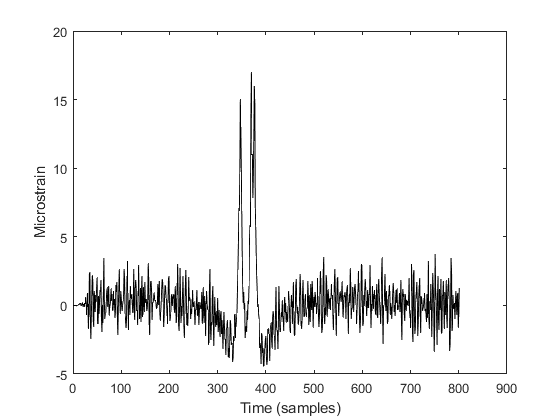

Data1 = textread('Run2.txt');
plot(Data1,'k', 'Linewidth', 1)
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test1_st40=Data1;
Test1_st40=Test1_st40(1:650);


Here, we denoise the strain response using wavelet denosing technique.

Test1_st40 = wdenoise(Test1_st40,3,'DenoisingMethod','BlockJS');


The envelope function is coded here to remove the global (non-localized) strain response. In this study, it was found that the ``Envelope'' function in MATLAB can successfully satisfy the requirements for global strain removal (explained in my dissertation) when a proper ``peak separation factor (n_p)'' is selected. The MATLAB code prepared for this study automatically checks different. $n_p$ values between 30-50 (found as the most effective range) and chooses the one that generates an envelope with smallest difference from P_1 (explained in my dissertation). To do this, a loop was programmed that changes the np value in each step and chooses the one with the lowest generated P_1 in the modified strain response (the non-localized response removed).

Please note that most of the time the selected np range works great but if for some cases it does not work properly, we slightly change the np range manually until it satisfies the requirements mentioned in the third chapter of my dissertation.

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test1] = envelope(Test1_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test1_st40_TRY=Test1_st40-low_test1;
  Cri_1(AA)=[abs(Test1_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));
if length(Index)>1
    Index=Index(1);
end
[up1,low_test1] = envelope(Test1_st40,XX(Index),'peak');
Test1_st40=Test1_st40-low_test1;


Now lets plot the modified strain response.

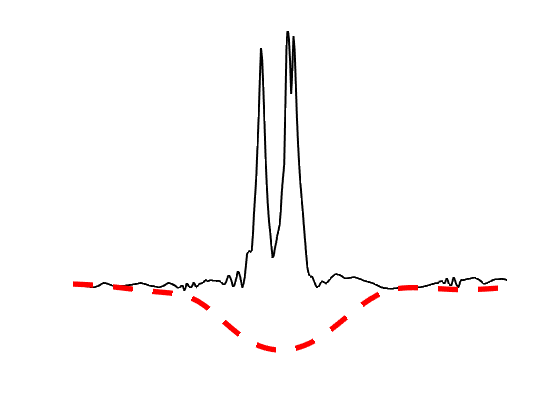

figure
plot(Test1_st40,'k', 'Linewidth', 1.5)
hold on
plot(low_test1,'--r', 'Linewidth', 4);
hold off

xlim([180 554])
ylim([-7 16])

ylabel('Microstrain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'w';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'w';

xlim([185 559])
ylim([-4.8 18.2])

Now, we isolate the modified strain response.

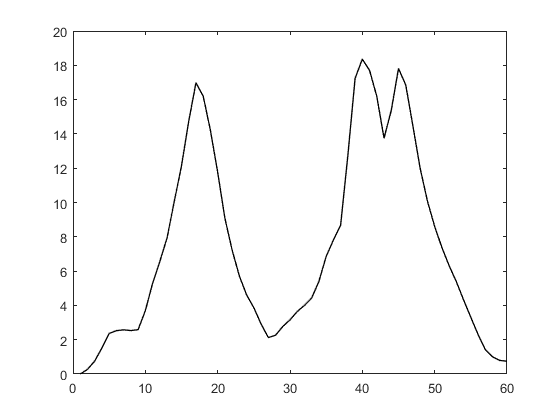

Test1_st40_L2=Test1_st40(331:390);

figure
plot(Test1_st40_L2,'k', 'Linewidth', 1)

## Inputs

Here we get the truck information. Please see the first paper (experimental case study) or my PhD dissertation (chapter 2) for details and to know what these parameters are. I have also commented them below for clarification.

N_T1=3;          %% the number of axles
v1_T1=20;        %% speed m/s
f_T1=100;        %% sampling rate (Hz)
d1_T1=0;         %% the distance of the first axle from the first axle (m) --> This is always zero
d2_T1=4.5;       %% the distance of the second axle from the first axle (m) 
d3_T1=1.31;      %% the distance of the third axle from the first axle (m)

% Axle weights

Weights_T1=[9.1 7.1 7.1];

% D vector using the d values already defined 

D1_vec_T1=[d1_T1 d1_T1+d2_T1 d1_T1+d2_T1+d3_T1];

% Calculating c values based on speed, sampling rate, and d values

c1_T1=D1_vec_T1(1)*f_T1/v1_T1;
c2_T1=D1_vec_T1(2)*f_T1/v1_T1;
c3_T1=D1_vec_T1(3)*f_T1/v1_T1;

C1_vec_T1=round([c1_T1 c2_T1 c3_T1]);

[row1_T1 col1_T1]=size(Test1_st40_L2);         
k1_T1=row1_T1;                      %% Total number of scans

[A_mat_T1_L2]=A_MATRIX(N_T1,k1_T1,C1_vec_T1,Weights_T1);


This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data) and returns the Matrix A. This matrix is later used for IL computation.

## Test 2 (3-axle_LANE2) "illustration"

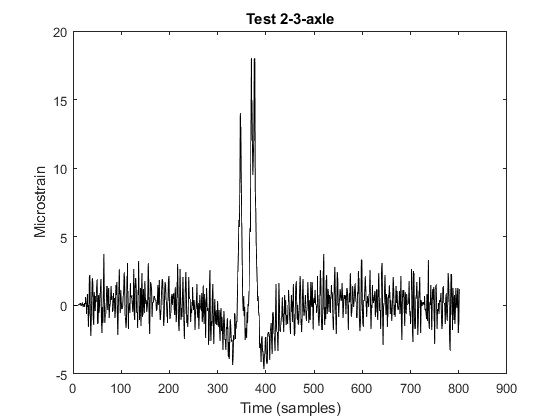

Data2 = textread('Run1_2.txt');
plot(Data2,'k', 'Linewidth', 1)
title('Test 2-3-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test2_st40=Data2;
% Test2_st40=Test2_st40(200:900);
Test2_st40 = wdenoise(Test2_st40,3,'DenoisingMethod','BlockJS');
% x=1:1:length(Test2_st40);
% y = movmean(Test2_st40,5);

Cri_1=[];
AA=1;

XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test2] = envelope(Test2_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test2_st40_TRY=Test2_st40-low_test2;
  Cri_1(AA)=[abs(Test2_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));
if length(Index)>1
    Index=Index(1)
end

Index = 1


XX(Index)

ans = 30

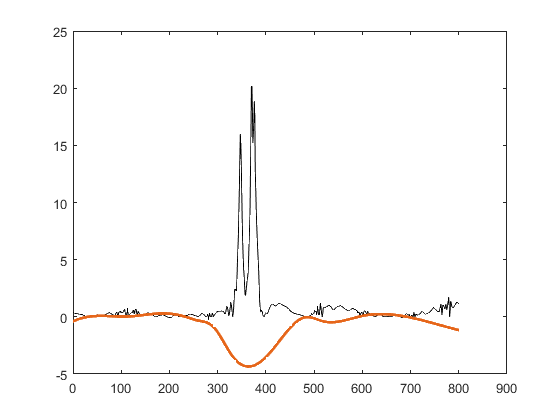

[up1,low_test2] = envelope(Test2_st40,XX(Index),'peak');
Test2_st40=Test2_st40-low_test2;


figure
plot(Test2_st40,'k', 'Linewidth', 1)
hold on
plot(low_test2,param_small{:});
hold off

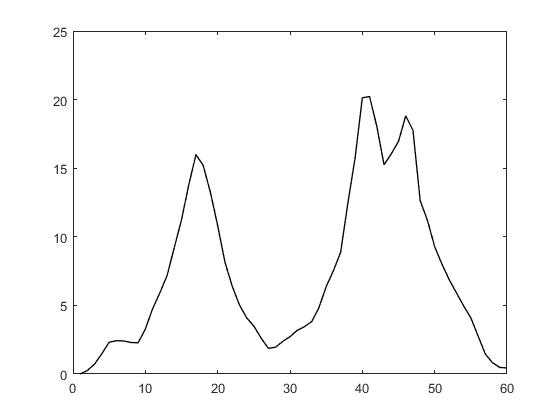

Test2_st40_L2=Test2_st40(331:390);

figure
plot(Test2_st40_L2,'k', 'Linewidth', 1)

## Inputs

N_T2=3;          %% the number of axles
v1_T2=20;     %% m/s
f_T2=100;         %% Hz
d1_T2=0;         %% m
d2_T2=4.6;      %% m
d3_T2=1.25;      %% m

Weights_T2=[8.2 7.5 7.5];

D1_vec_T2=[d1_T2 d1_T2+d2_T2 d1_T2+d2_T2+d3_T2];

c1_T2=D1_vec_T2(1)*f_T2/v1_T2;
c2_T2=D1_vec_T2(2)*f_T2/v1_T2;
c3_T2=D1_vec_T2(3)*f_T2/v1_T2;

C1_vec_T2=round([c1_T2 c2_T2 c3_T2]);

[row1_T2 col1_T2]=size(Test2_st40_L2);         
k1_T2=row1_T2;                      %% Total number of scans

[A_mat_T2_L2]=A_MATRIX(N_T2,k1_T2,C1_vec_T2,Weights_T2);


## Test 3 (3-axle_LANE2) "illustration"

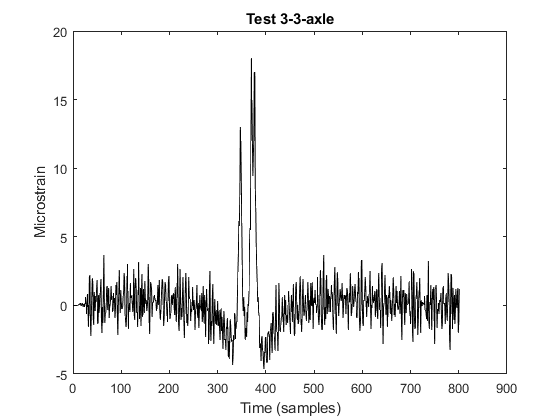

Data3 = textread('Run13.txt');
plot(Data3,'k', 'Linewidth', 1)
title('Test 3-3-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test3_st40=Data3;
% Test3_st40=Test3_st40(200:900);
Test3_st40 = wdenoise(Test3_st40,3,'DenoisingMethod','BlockJS');
% x=1:1:length(Test3_st40);
% y = movmean(Test3_st40,5);

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test3] = envelope(Test3_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test3_st40_TRY=Test3_st40-low_test3;
  Cri_1(AA)=[abs(Test3_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));
if length(Index)>1
    Index=Index(1)
end

Index = 1


XX(Index)

ans = 30

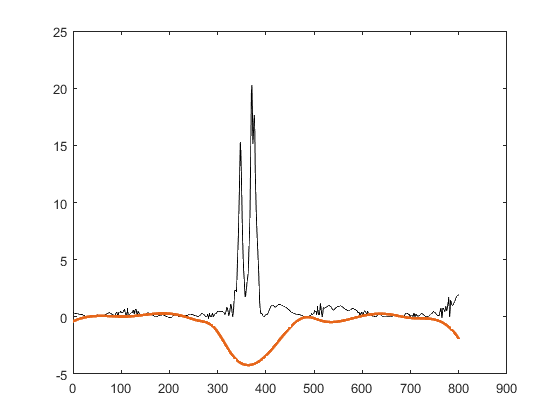

[up1,low_test3] = envelope(Test3_st40,XX(Index),'peak');
Test3_st40=Test3_st40-low_test3;



figure
plot(Test3_st40,'k', 'Linewidth', 1)
hold on
plot(low_test3,param_small{:});
hold off

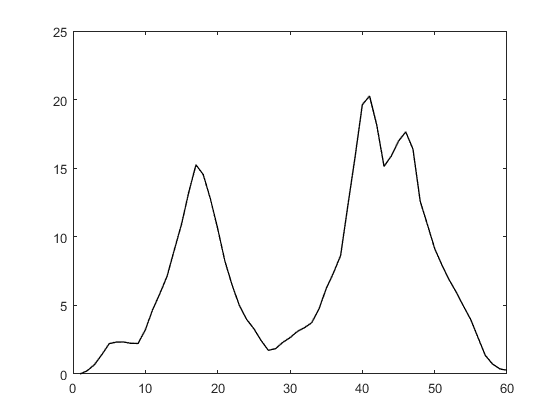

Test3_st40_L2=Test3_st40(331:390);

figure
plot(Test3_st40_L2,'k', 'Linewidth', 1)

## Inputs

N_T3=3;          %% the number of axles
v1_T3=20;     %% m/s
f_T3=100;         %% Hz
d1_T3=0;         %% m
d2_T3=4.6;      %% m
d3_T3=1.25;      %% m

Weights_T3=[8.2 7.5 7.5];

D1_vec_T3=[d1_T3 d1_T3+d2_T3 d1_T3+d2_T3+d3_T3];

c1_T3=D1_vec_T3(1)*f_T3/v1_T3;
c2_T3=D1_vec_T3(2)*f_T3/v1_T3;
c3_T3=D1_vec_T3(3)*f_T3/v1_T3;

C1_vec_T3=round([c1_T3 c2_T3 c3_T3]);

[row1_T3 col1_T3]=size(Test3_st40_L2);         
k1_T3=row1_T3;                      %% Total number of scans

[A_mat_T3_L2]=A_MATRIX(N_T3,k1_T3,C1_vec_T3,Weights_T3);

## Test 5 (5-axle_LANE2) "illustration"

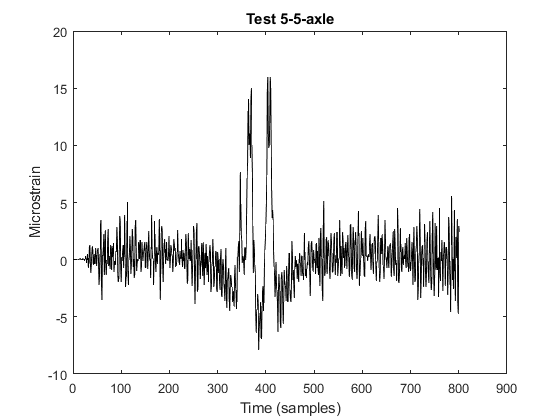

Data5 = textread('Run5_2.txt');
plot(Data5,'k', 'Linewidth', 1)
title('Test 5-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test5_st40=Data5;
Test5_st40=Test5_st40(200:500);
Test5_st40 = wdenoise(Test5_st40,3,'DenoisingMethod','BlockJS');
% x=1:1:length(Test5_st40);
% y = movmean(Test5_st40,5);

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test5] = envelope(Test5_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test5_st40_TRY=Test5_st40-low_test5;
  Cri_1(AA)=[abs(Test5_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));
if length(Index)>1
    Index=Index(1)
end

XX(Index)

ans = 35

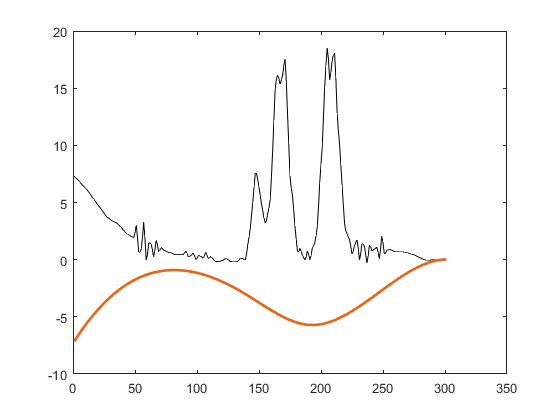

[up1,low_test5] = envelope(Test5_st40,XX(Index),'peak');
Test5_st40=Test5_st40-low_test5;



figure
plot(Test5_st40,'k', 'Linewidth', 1)
hold on
plot(low_test5,param_small{:});
hold off

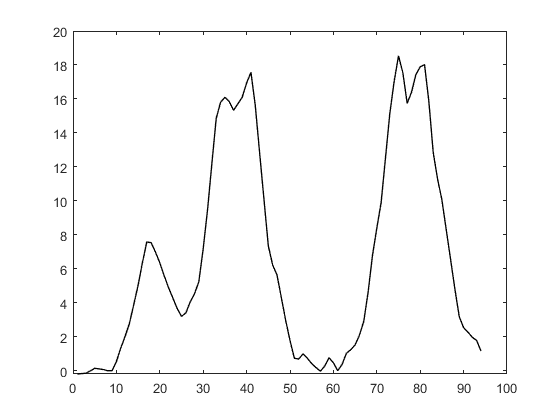

Test5_st40_L2=Test5_st40(131:224);

figure
plot(Test5_st40_L2,'k', 'Linewidth', 1)

## Inputs

N_T5=5;          %% the number of axles
v1_T5=20;     %% m/s
f_T5=100;        %% Hz
d1_T5=0;         %% m
d2_T5=3.35;      %% m
d3_T5=1.22;      %% m
d4_T5=6.71;     %% m
d5_T5=1.22;      %% m


Weights_T5=[4.5 7.1 7.1 7.1 7.1];

D1_vec_T5=[d1_T5 d1_T5+d2_T5 d1_T5+d2_T5+d3_T5 d1_T5+d2_T5+d3_T5+d4_T5 d1_T5+d2_T5+d3_T5+d4_T5+d5_T5];

c1_T5=D1_vec_T5(1)*f_T5/v1_T5;
c2_T5=D1_vec_T5(2)*f_T5/v1_T5;
c3_T5=D1_vec_T5(3)*f_T5/v1_T5;
c4_T5=D1_vec_T5(4)*f_T5/v1_T5;
c5_T5=D1_vec_T5(5)*f_T5/v1_T5;

C1_vec_T5=round([c1_T5 c2_T5 c3_T5 c4_T5 c5_T5]);

[row1_T5 col1_T5]=size(Test5_st40_L2);
k1_T5=row1_T5;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T5_L2]=A_MATRIX(N_T5,k1_T5,C1_vec_T5,Weights_T5);


## Test 6 (5-axle_LANE2) "illustration"

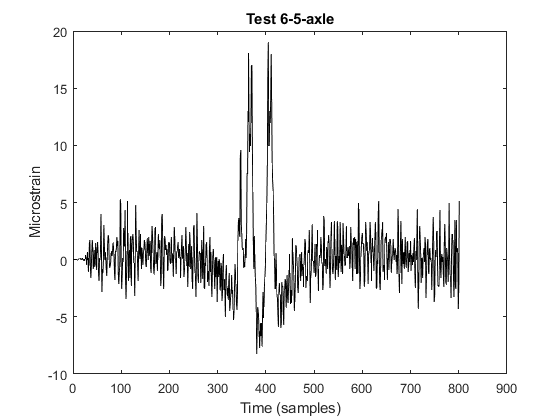

Data6 = textread('Run6.txt');
plot(Data6,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test6_st40=Data6;
Test6_st40=Test6_st40(100:600);
Test6_st40 = wdenoise(Test6_st40,3,'DenoisingMethod','BlockJS');
% x=1:1:length(Test6_st40);
% y = movmean(Test6_st40,5);

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test6] = envelope(Test6_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test6_st40_TRY=Test6_st40-low_test6;
  Cri_1(AA)=[abs(Test6_st40_TRY(233,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

XX(Index)

ans = 35

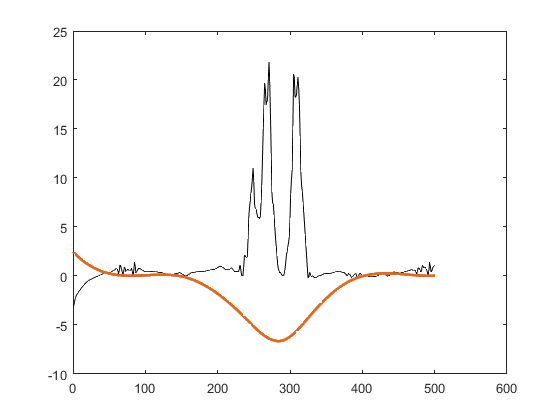

[up1,low_test6] = envelope(Test6_st40,XX(Index),'peak');
Test6_st40=Test6_st40-low_test6;



figure
plot(Test6_st40,'k', 'Linewidth', 1)
hold on
plot(low_test6,param_small{:});
hold off

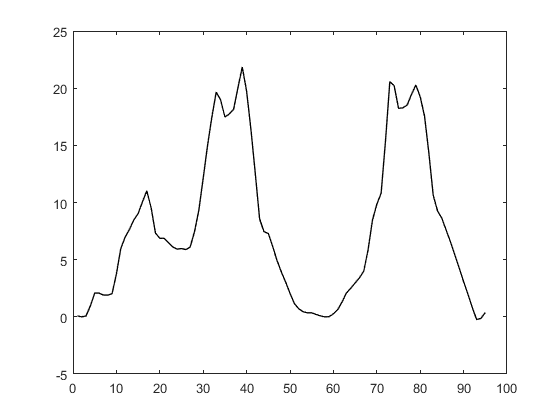

Test6_st40_L2=Test6_st40(233:327);

figure
plot(Test6_st40_L2,'k', 'Linewidth', 1)

## Inputs

N_T6=5;          %% the number of axles
v1_T6=20;     %% m/s
f_T6=100;        %% Hz
d1_T6=0;         %% m
d2_T6=3.4;      %% m
d3_T6=1.31;      %% m
d4_T6=6.78;     %% m
d5_T6=1.31;      %% m


Weights_T6=[6.2 8 8.2 8 8.2];

D1_vec_T6=[d1_T6 d1_T6+d2_T6 d1_T6+d2_T6+d3_T6 d1_T6+d2_T6+d3_T6+d4_T6 d1_T6+d2_T6+d3_T6+d4_T6+d5_T6];

c1_T6=D1_vec_T6(1)*f_T6/v1_T6;
c2_T6=D1_vec_T6(2)*f_T6/v1_T6;
c3_T6=D1_vec_T6(3)*f_T6/v1_T6;
c4_T6=D1_vec_T6(4)*f_T6/v1_T6;
c5_T6=D1_vec_T6(5)*f_T6/v1_T6;

C1_vec_T6=round([c1_T6 c2_T6 c3_T6 c4_T6 c5_T6]);

[row1_T6 col1_T6]=size(Test6_st40_L2);
k1_T6=row1_T6;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T6_L2]=A_MATRIX(N_T6,k1_T6,C1_vec_T6,Weights_T6);


The following test and the one after are used to compute the IL for lane 2. These two tests are with the same number of axles (4axle) on lane two but with different axle spacings and axle weights. These parameters are specified in "Input" part.

## Test 7 (4-axle_LANE2) "calibration"

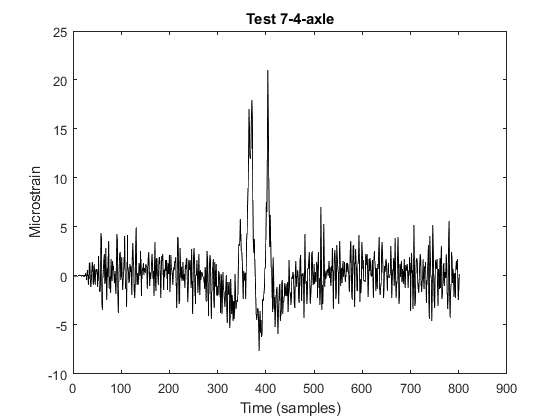

Data7 = textread('Run9_2.txt');
plot(Data7,'k', 'Linewidth', 1)
title('Test 7-4-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

Test7_st40=Data7;
Test7_st40 = wdenoise(Test7_st40,3,'DenoisingMethod','BlockJS');


Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test7] = envelope(Test7_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test7_st40_TRY=Test7_st40-low_test7;
  Cri_1(AA)=[abs(Test7_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));
XX(Index)

ans =     30    35    40    45    50


if length(Index)>1
    Index=Index(1);
end
[up1,low_test7] = envelope(Test7_st40,XX(Index),'peak');
Test7_st40=Test7_st40-low_test7;



The fitted curve may not look pretty smooth but satisfies the requirements. If you want a pretty smooth fit, you should apply a moving mean smoother on the region outside the localize strain but it is not necessary.

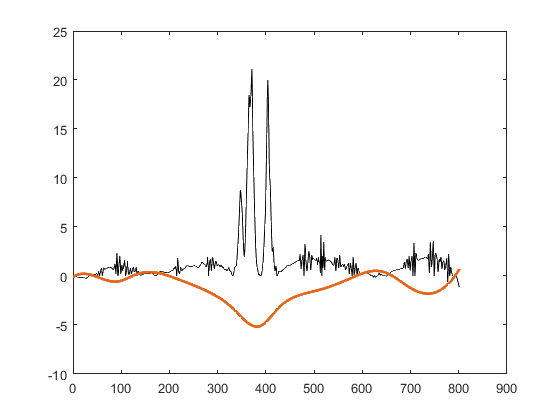

figure
plot(Test7_st40,'k', 'Linewidth', 1)
hold on
plot(low_test7,param_small{:});
hold off

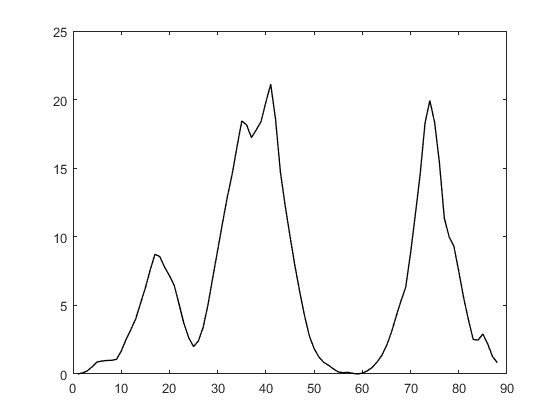

Test7_st40_L2=Test7_st40(331:418);

figure
plot(Test7_st40_L2,'k', 'Linewidth', 1)

## Inputs

N_T7=4;          %% the number of axles
v1_T7=20;     %% m/s
f_T7=100;        %% Hz
d1_T7=0;         %% m
d2_T7=3.6;      %% m
d3_T7=1.2;      %% m
d4_T7=6.6;     %% m



Weights_T7=[5.1 8.3 8.3 10.4];

D1_vec_T7=[d1_T7 d1_T7+d2_T7 d1_T7+d2_T7+d3_T7 d1_T7+d2_T7+d3_T7+d4_T7];

c1_T7=D1_vec_T7(1)*f_T7/v1_T7;
c2_T7=D1_vec_T7(2)*f_T7/v1_T7;
c3_T7=D1_vec_T7(3)*f_T7/v1_T7;
c4_T7=D1_vec_T7(4)*f_T7/v1_T7;


C1_vec_T7=round([c1_T7 c2_T7 c3_T7 c4_T7]);

[row1_T7 col1_T7]=size(Test7_st40_L2);
k1_T7=row1_T7;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T7_L2]=A_MATRIX(N_T7,k1_T7,C1_vec_T7,Weights_T7);


## Test 8 (4-axle_LANE2) "calibration"

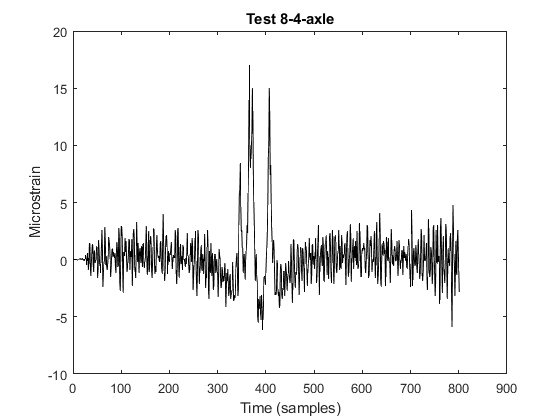

Data8 = textread('Run10.txt');
plot(Data8,'k', 'Linewidth', 1)
title('Test 8-4-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test8_st40=Data8;
Test8_st40=Test8_st40(100:600);
Test8_st40 = wdenoise(Test8_st40,3,'DenoisingMethod','BlockJS');
% x=1:1:length(Test8_st40);
% Test8_st40 = movmean(Test8_st40,10);

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test8] = envelope(Test8_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test8_st40_TRY=Test8_st40-low_test8;
  Cri_1(AA)=[abs(Test8_st40_TRY(231,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

XX(Index)

ans = 30

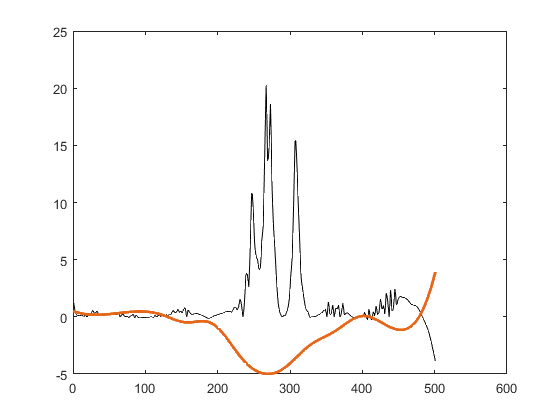


[up1,low_test8] = envelope(Test8_st40,XX(Index),'peak');
Test8_st40=Test8_st40-low_test8;



figure
plot(Test8_st40,'k', 'Linewidth', 1)
hold on
plot(low_test8,param_small{:});
hold off

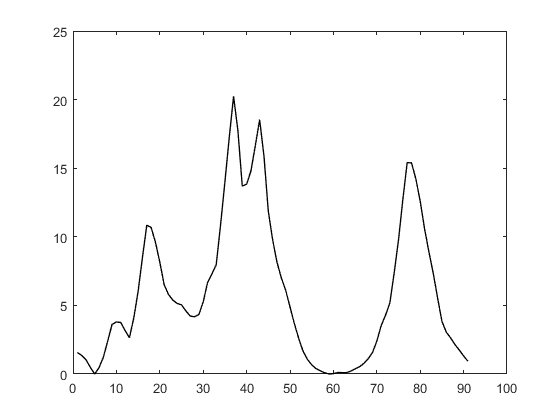

Test8_st40_L2=Test8_st40(231:321);

figure
plot(Test8_st40_L2,'k', 'Linewidth', 1)

## Inputs

N_T8=4;          %% the number of axles
v1_T8=20;     %% m/s
f_T8=100;        %% Hz
d1_T8=0;         %% m
d2_T8=3.7;      %% m
d3_T8=1.32;      %% m
d4_T8=7;     %% m



Weights_T8=[5.3 7 7 8.5];

D1_vec_T8=[d1_T8 d1_T8+d2_T8 d1_T8+d2_T8+d3_T8 d1_T8+d2_T8+d3_T8+d4_T8];

c1_T8=D1_vec_T8(1)*f_T8/v1_T8;
c2_T8=D1_vec_T8(2)*f_T8/v1_T8;
c3_T8=D1_vec_T8(3)*f_T8/v1_T8;
c4_T8=D1_vec_T8(4)*f_T8/v1_T8;


C1_vec_T8=round([c1_T8 c2_T8 c3_T8 c4_T8]);

[row1_T8 col1_T8]=size(Test8_st40_L2);
k1_T8=row1_T8;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T8_L2]=A_MATRIX(N_T8,k1_T8,C1_vec_T8,Weights_T8);


## Test 1 (3-axle_LANE1) "illustration"

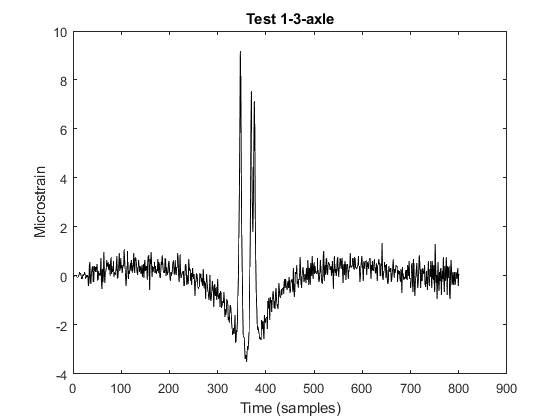

Data1 = textread('Run4.txt');
% Data1 =Data1(250:430);
plot(Data1,'k', 'Linewidth', 1)
title('Test 1-3-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test1_st40=Data1;
Test1_st40=Test1_st40(1:650);
Test1_st40 = wdenoise(Test1_st40,3,'DenoisingMethod','BlockJS');
% x=1:1:length(Test1_st40);
% Test1_st40= movmean(Test1_st40,5);

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test1] = envelope(Test1_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test1_st40_TRY=Test1_st40-low_test1;
  Cri_1(AA)=[abs(Test1_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));
if length(Index)>1
    Index=Index(1)
end

XX(Index)

ans = 40

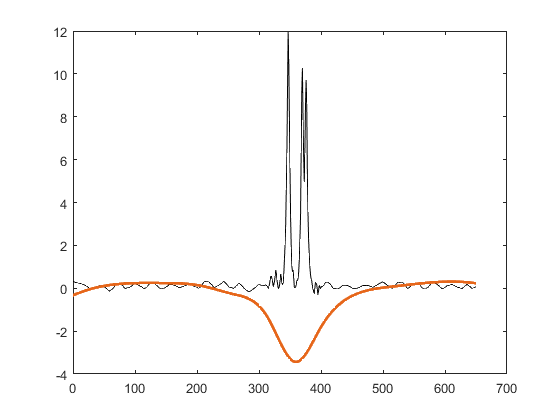

[up1,low_test1] = envelope(Test1_st40,XX(Index),'peak');
Test1_st40=Test1_st40-low_test1;



figure
plot(Test1_st40,'k', 'Linewidth', 1)
hold on
plot(low_test1,param_small{:});
hold off

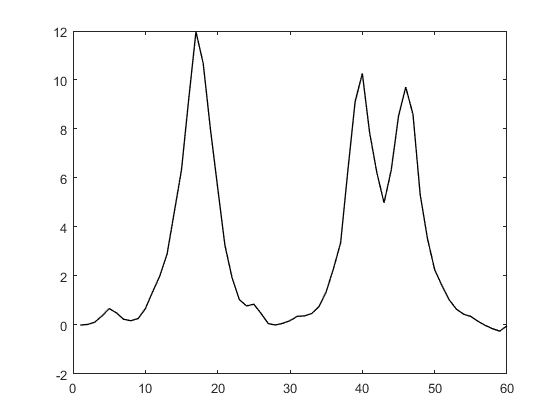

Test1_st40_L1=Test1_st40(331:390);

figure
plot(Test1_st40_L1,'k', 'Linewidth', 1)

## Inputs

N_T1=3;          %% the number of axles
v1_T1=20;     %% m/s
f_T1=100;         %% Hz
d1_T1=0;         %% m
d2_T1=4.5;      %% m
d3_T1=1.31;      %% m

Weights_T1=[9.1 7.1 7.1];

D1_vec_T1=[d1_T1 d1_T1+d2_T1 d1_T1+d2_T1+d3_T1];

c1_T1=D1_vec_T1(1)*f_T1/v1_T1;
c2_T1=D1_vec_T1(2)*f_T1/v1_T1;
c3_T1=D1_vec_T1(3)*f_T1/v1_T1;

C1_vec_T1=round([c1_T1 c2_T1 c3_T1]);

[row1_T1 col1_T1]=size(Test1_st40_L1);         
k1_T1=row1_T1;                      %% Total number of scans

[A_mat_T1_L1]=A_MATRIX(N_T1,k1_T1,C1_vec_T1,Weights_T1);
% 

## Test 2 (3-axle_LANE1) "illustration"

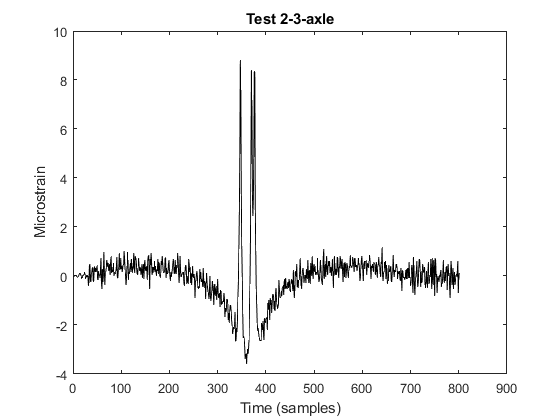

Data2 = textread('Run3_2.txt');
plot(Data2,'k', 'Linewidth', 1)
title('Test 2-3-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test2_st40=Data2;
% Test2_st40=Test2_st40(200:900);
Test2_st40 = wdenoise(Test2_st40,3,'DenoisingMethod','BlockJS');
% x=1:1:length(Test2_st40);
% y = movmean(Test2_st40,5);

Cri_1=[];
AA=1;

XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test2] = envelope(Test2_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test2_st40_TRY=Test2_st40-low_test2;
  Cri_1(AA)=[abs(Test2_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));
if length(Index)>1
    Index=Index(1)
end

XX(Index)

ans = 35

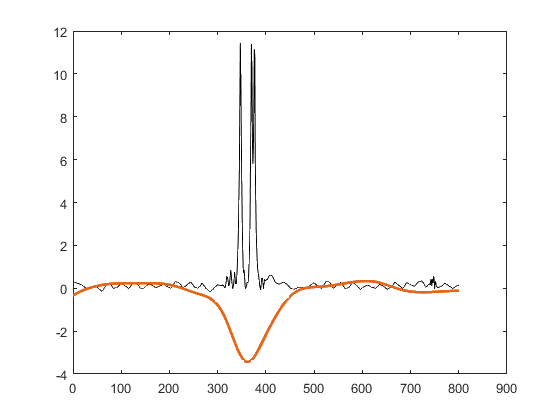

[up1,low_test2] = envelope(Test2_st40,XX(Index),'peak');
Test2_st40=Test2_st40-low_test2;



figure
plot(Test2_st40,'k', 'Linewidth', 1)
hold on
plot(low_test2,param_small{:});
hold off

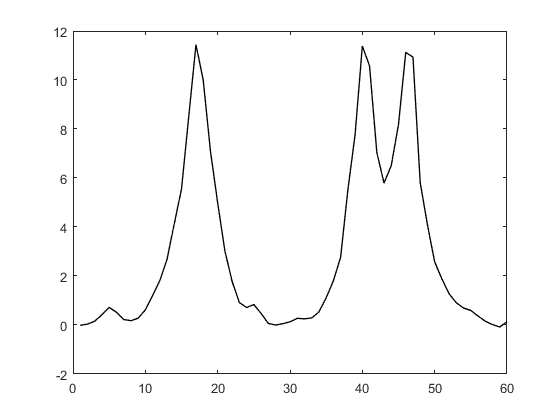

Test2_st40_L1=Test2_st40(331:390);

figure
plot(Test2_st40_L1,'k', 'Linewidth', 1)

## Inputs

N_T2=3;          %% the number of axles
v1_T2=20;     %% m/s
f_T2=100;         %% Hz
d1_T2=0;         %% m
d2_T2=4.6;      %% m
d3_T2=1.25;      %% m

Weights_T2=[8.2 7.5 7.5];

D1_vec_T2=[d1_T2 d1_T2+d2_T2 d1_T2+d2_T2+d3_T2];

c1_T2=D1_vec_T2(1)*f_T2/v1_T2;
c2_T2=D1_vec_T2(2)*f_T2/v1_T2;
c3_T2=D1_vec_T2(3)*f_T2/v1_T2;

C1_vec_T2=round([c1_T2 c2_T2 c3_T2]);

[row1_T2 col1_T2]=size(Test2_st40_L1);         
k1_T2=row1_T2;                      %% Total number of scans

[A_mat_T2_L1]=A_MATRIX(N_T2,k1_T2,C1_vec_T2,Weights_T2);


## Test 3 (3-axle_LANE1) "illustration"

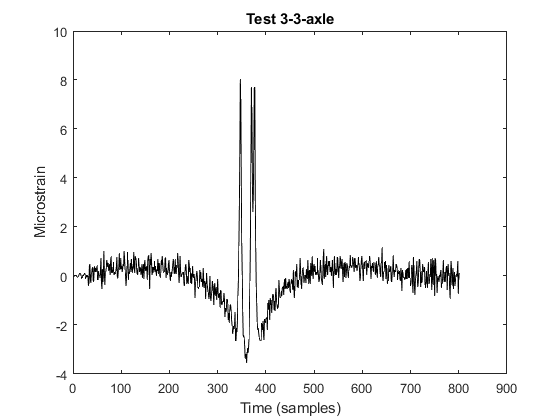

Data3 = textread('Run14.txt');
plot(Data3,'k', 'Linewidth', 1)
title('Test 3-3-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test3_st40=Data3;
% Test3_st40=Test3_st40(200:900);
Test3_st40 = wdenoise(Test3_st40,3,'DenoisingMethod','BlockJS');
% x=1:1:length(Test3_st40);
% y = movmean(Test3_st40,5);

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test3] = envelope(Test3_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test3_st40_TRY=Test3_st40-low_test3;
  Cri_1(AA)=[abs(Test3_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));
if length(Index)>1
    Index=Index(1)
end

XX(Index)

ans = 40

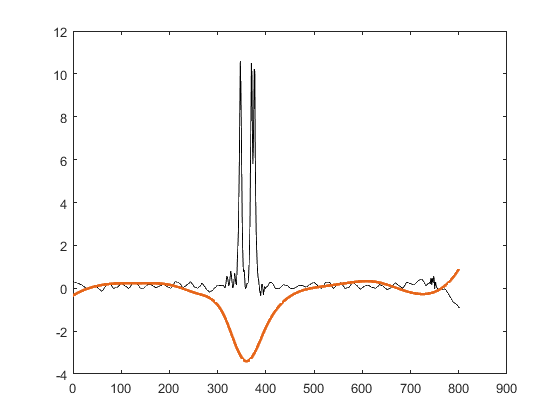

[up1,low_test3] = envelope(Test3_st40,XX(Index),'peak');
Test3_st40=Test3_st40-low_test3;


figure
plot(Test3_st40,'k', 'Linewidth', 1)
hold on
plot(low_test3,param_small{:});
hold off

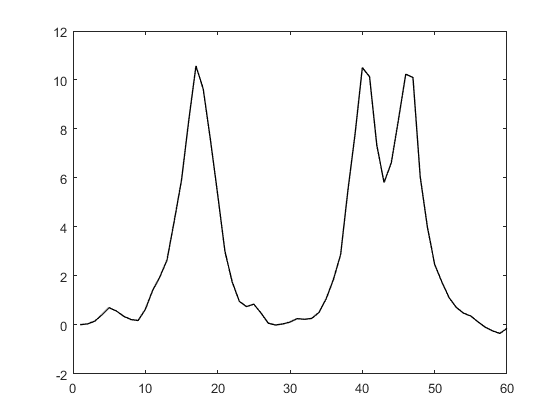

Test3_st40_L1=Test3_st40(331:390);

figure
plot(Test3_st40_L1,'k', 'Linewidth', 1)

## Inputs

N_T3=3;          %% the number of axles
v1_T3=20;     %% m/s
f_T3=100;         %% Hz
d1_T3=0;         %% m
d2_T3=4.6;      %% m
d3_T3=1.25;      %% m

Weights_T3=[8.2 7.5 7.5];

D1_vec_T3=[d1_T3 d1_T3+d2_T3 d1_T3+d2_T3+d3_T3];

c1_T3=D1_vec_T3(1)*f_T3/v1_T3;
c2_T3=D1_vec_T3(2)*f_T3/v1_T3;
c3_T3=D1_vec_T3(3)*f_T3/v1_T3;

C1_vec_T3=round([c1_T3 c2_T3 c3_T3]);

[row1_T3 col1_T3]=size(Test3_st40_L1);         
k1_T3=row1_T3;                      %% Total number of scans

[A_mat_T3_L1]=A_MATRIX(N_T3,k1_T3,C1_vec_T3,Weights_T3);

## Test 5 (5-axle_LANE1) "illustration"

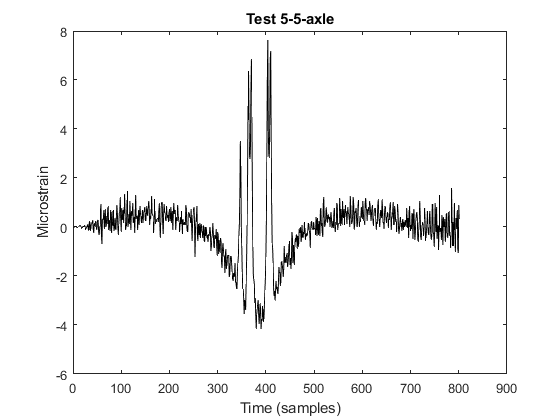

Data5 = textread('Run7_2.txt');
plot(Data5,'k', 'Linewidth', 1)
title('Test 5-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test5_st40=Data5;
Test5_st40=Test5_st40(200:500);
Test5_st40 = wdenoise(Test5_st40,3,'DenoisingMethod','BlockJS');
% x=1:1:length(Test5_st40);
% y = movmean(Test5_st40,5);

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test5] = envelope(Test5_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test5_st40_TRY=Test5_st40-low_test5;
  Cri_1(AA)=[abs(Test5_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));
if length(Index)>1
    Index=Index(1)
end

XX(Index)

ans = 30

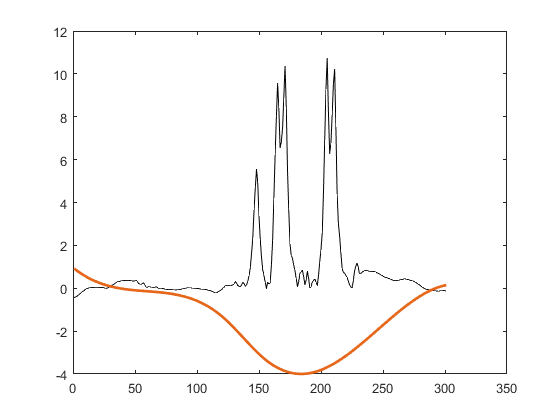

[up1,low_test5] = envelope(Test5_st40,XX(Index),'peak');
Test5_st40=Test5_st40-low_test5;



figure
plot(Test5_st40,'k', 'Linewidth', 1)
hold on
plot(low_test5,param_small{:});
hold off

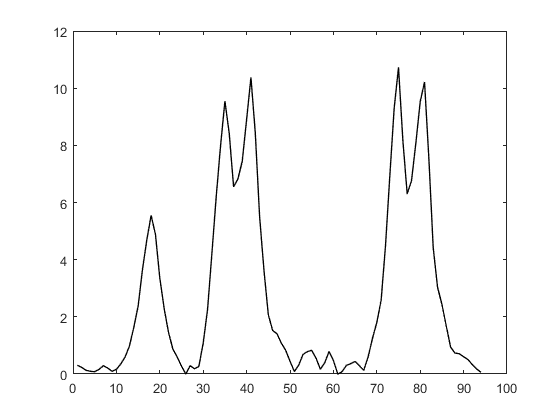

Test5_st40_L1=Test5_st40(131:224);

figure
plot(Test5_st40_L1,'k', 'Linewidth', 1)

## Inputs

N_T5=5;          %% the number of axles
v1_T5=20;     %% m/s
f_T5=100;        %% Hz
d1_T5=0;         %% m
d2_T5=3.35;      %% m
d3_T5=1.22;      %% m
d4_T5=6.71;     %% m
d5_T5=1.22;      %% m


Weights_T5=[4.5 7.1 7.1 7.1 7.1];

D1_vec_T5=[d1_T5 d1_T5+d2_T5 d1_T5+d2_T5+d3_T5 d1_T5+d2_T5+d3_T5+d4_T5 d1_T5+d2_T5+d3_T5+d4_T5+d5_T5];

c1_T5=D1_vec_T5(1)*f_T5/v1_T5;
c2_T5=D1_vec_T5(2)*f_T5/v1_T5;
c3_T5=D1_vec_T5(3)*f_T5/v1_T5;
c4_T5=D1_vec_T5(4)*f_T5/v1_T5;
c5_T5=D1_vec_T5(5)*f_T5/v1_T5;

C1_vec_T5=round([c1_T5 c2_T5 c3_T5 c4_T5 c5_T5]);

[row1_T5 col1_T5]=size(Test5_st40_L1);
k1_T5=row1_T5;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T5_L1]=A_MATRIX(N_T5,k1_T5,C1_vec_T5,Weights_T5);


## Test 6 (5-axle_LANE1) "illustration"

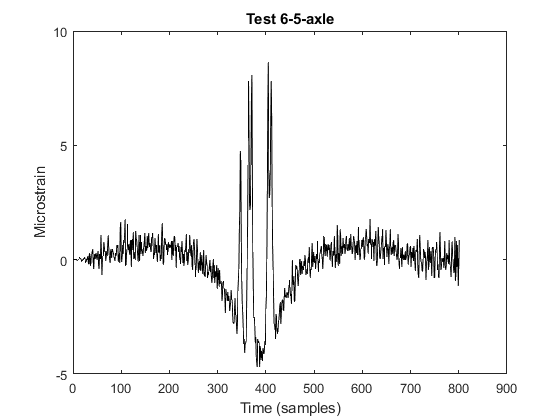

Data6 = textread('Run8.txt');
plot(Data6,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test6_st40=Data6;
Test6_st40=Test6_st40(100:600);
Test6_st40 = wdenoise(Test6_st40,3,'DenoisingMethod','BlockJS');
% x=1:1:length(Test6_st40);
% y = movmean(Test6_st40,5);

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test6] = envelope(Test6_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test6_st40_TRY=Test6_st40-low_test6;
  Cri_1(AA)=[abs(Test6_st40_TRY(233,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

XX(Index)

ans = 35

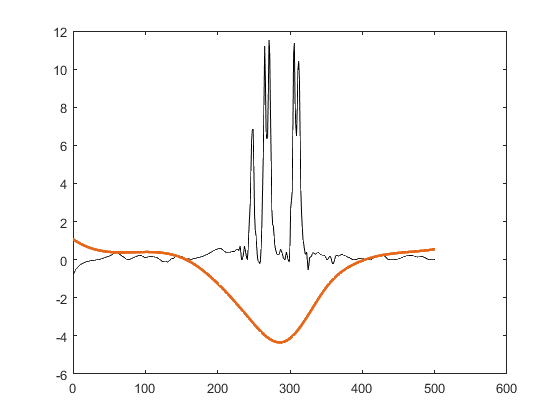

[up1,low_test6] = envelope(Test6_st40,XX(Index),'peak');
Test6_st40=Test6_st40-low_test6;



figure
plot(Test6_st40,'k', 'Linewidth', 1)
hold on
plot(low_test6,param_small{:});
hold off

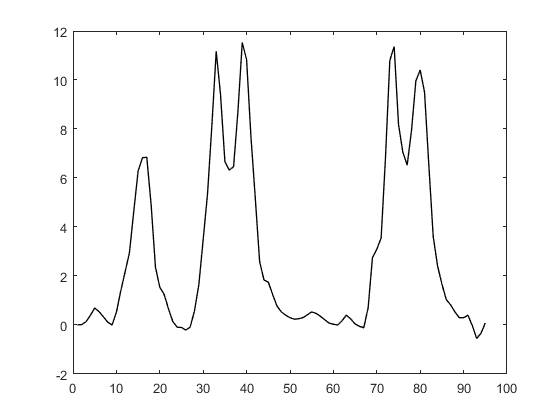

Test6_st40_L1=Test6_st40(233:327);

figure
plot(Test6_st40_L1,'k', 'Linewidth', 1)

## Inputs

N_T6=5;          %% the number of axles
v1_T6=20;     %% m/s
f_T6=100;        %% Hz
d1_T6=0;         %% m
d2_T6=3.4;      %% m
d3_T6=1.31;      %% m
d4_T6=6.78;     %% m
d5_T6=1.31;      %% m


Weights_T6=[6.2 8 8.2 8 8.2];

D1_vec_T6=[d1_T6 d1_T6+d2_T6 d1_T6+d2_T6+d3_T6 d1_T6+d2_T6+d3_T6+d4_T6 d1_T6+d2_T6+d3_T6+d4_T6+d5_T6];

c1_T6=D1_vec_T6(1)*f_T6/v1_T6;
c2_T6=D1_vec_T6(2)*f_T6/v1_T6;
c3_T6=D1_vec_T6(3)*f_T6/v1_T6;
c4_T6=D1_vec_T6(4)*f_T6/v1_T6;
c5_T6=D1_vec_T6(5)*f_T6/v1_T6;

C1_vec_T6=round([c1_T6 c2_T6 c3_T6 c4_T6 c5_T6]);

[row1_T6 col1_T6]=size(Test6_st40_L1);
k1_T6=row1_T6;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T6_L1]=A_MATRIX(N_T6,k1_T6,C1_vec_T6,Weights_T6);


Tests 7 and 8 are on lane 1 to compute the IL for lane 1. The difference between these two tests is the axle spacings and axle weights.

## Test 7 (4-axle_LANE1) "calibration"

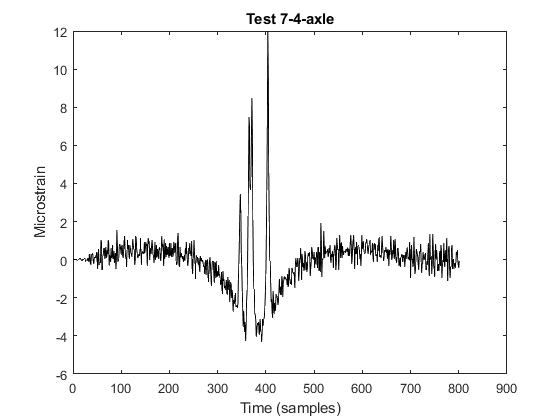

Data7 = textread('Run11_2.txt');
plot(Data7,'k', 'Linewidth', 1)
title('Test 7-4-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test7_st40=Data7;
% Test7_st40=Test7_st40(100:600);
Test7_st40 = wdenoise(Test7_st40,3,'DenoisingMethod','BlockJS');
% Test7_st40 = movmean(Test7_st40,7);

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test7] = envelope(Test7_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test7_st40_TRY=Test7_st40-low_test7;
  Cri_1(AA)=[abs(Test7_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));
XX(Index)

ans =     35    40    45


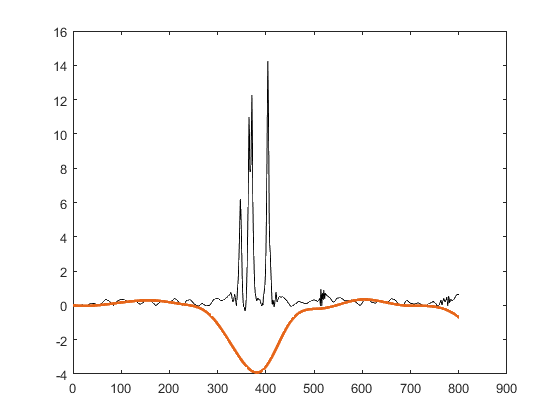

if length(Index)>1
    Index=Index(1);
end
[up1,low_test7] = envelope(Test7_st40,XX(Index),'peak');
Test7_st40=Test7_st40-low_test7;




figure
plot(Test7_st40,'k', 'Linewidth', 1)
hold on
plot(low_test7,param_small{:});
hold off

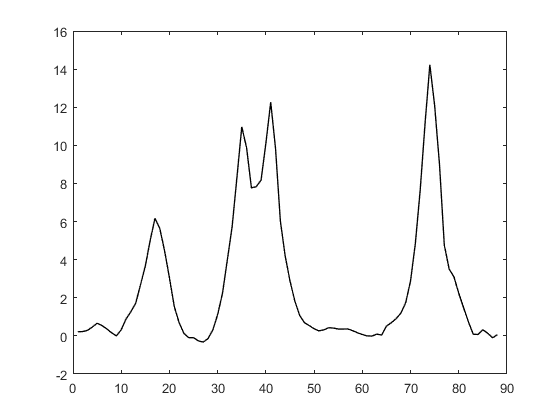

Test7_st40_L1=Test7_st40(331:418);

figure
plot(Test7_st40_L1,'k', 'Linewidth', 1)

## Inputs

N_T7=4;          %% the number of axles
v1_T7=20;     %% m/s
f_T7=100;        %% Hz
d1_T7=0;         %% m
d2_T7=3.6;      %% m
d3_T7=1.2;      %% m
d4_T7=6.6;     %% m



Weights_T7=[5.1 8.3 8.3 10.4];

D1_vec_T7=[d1_T7 d1_T7+d2_T7 d1_T7+d2_T7+d3_T7 d1_T7+d2_T7+d3_T7+d4_T7];

c1_T7=D1_vec_T7(1)*f_T7/v1_T7;
c2_T7=D1_vec_T7(2)*f_T7/v1_T7;
c3_T7=D1_vec_T7(3)*f_T7/v1_T7;
c4_T7=D1_vec_T7(4)*f_T7/v1_T7;


C1_vec_T7=round([c1_T7 c2_T7 c3_T7 c4_T7]);

[row1_T7 col1_T7]=size(Test7_st40_L1);
k1_T7=row1_T7;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T7_L1]=A_MATRIX(N_T7,k1_T7,C1_vec_T7,Weights_T7);

## Test 8 (4-axle_LANE1) "calibration"

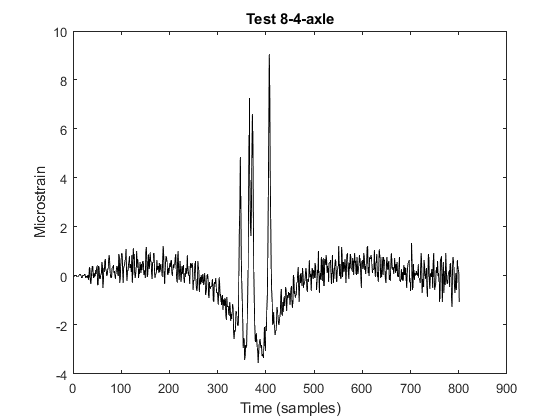

Data8 = textread('Run12.txt');
plot(Data8,'k', 'Linewidth', 1)
title('Test 8-4-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Test8_st40=Data8;
Test8_st40=Test8_st40(100:600);
Test8_st40 = wdenoise(Test8_st40,3,'DenoisingMethod','BlockJS');
% x=1:1:length(Test8_st40);
% Test8_st40 = movmean(Test8_st40,10);

Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test8] = envelope(Test8_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test8_st40_TRY=Test8_st40-low_test8;
  Cri_1(AA)=[abs(Test8_st40_TRY(231,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

XX(Index)

ans = 30

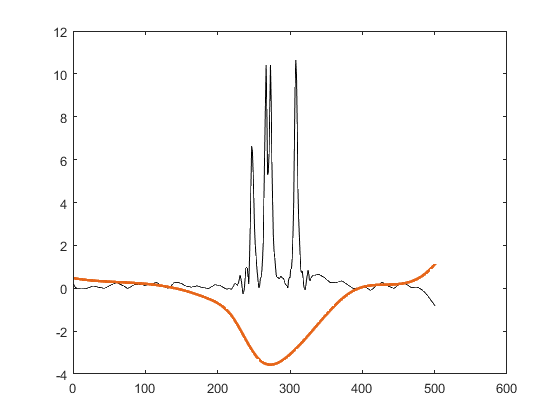


[up1,low_test8] = envelope(Test8_st40,XX(Index),'peak');
Test8_st40=Test8_st40-low_test8;



figure
plot(Test8_st40,'k', 'Linewidth', 1)
hold on
plot(low_test8,param_small{:});
hold off

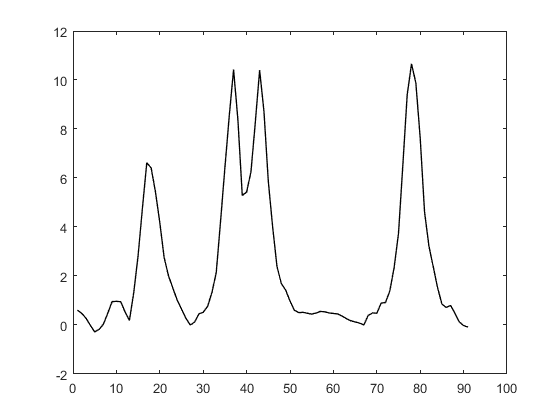

Test8_st40_L1=Test8_st40(231:321);

figure
plot(Test8_st40_L1,'k', 'Linewidth', 1)

## Inputs

N_T8=4;          %% the number of axles
v1_T8=20;     %% m/s
f_T8=100;        %% Hz
d1_T8=0;         %% m
d2_T8=3.7;      %% m
d3_T8=1.32;      %% m
d4_T8=7;     %% m



Weights_T8=[5.3 7 7 8.5];

D1_vec_T8=[d1_T8 d1_T8+d2_T8 d1_T8+d2_T8+d3_T8 d1_T8+d2_T8+d3_T8+d4_T8];

c1_T8=D1_vec_T8(1)*f_T8/v1_T8;
c2_T8=D1_vec_T8(2)*f_T8/v1_T8;
c3_T8=D1_vec_T8(3)*f_T8/v1_T8;
c4_T8=D1_vec_T8(4)*f_T8/v1_T8;


C1_vec_T8=round([c1_T8 c2_T8 c3_T8 c4_T8]);

[row1_T8 col1_T8]=size(Test8_st40_L1);
k1_T8=row1_T8;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T8_L1]=A_MATRIX(N_T8,k1_T8,C1_vec_T8,Weights_T8);

## Influence Line 


Inf_Line_L2=inv(A_mat_T7_L2'*A_mat_T7_L2+A_mat_T8_L2'*A_mat_T8_L2)*(A_mat_T7_L2'*Test7_st40_L2+A_mat_T8_L2'*Test8_st40_L2);
Inf_Line_L1=inv(A_mat_T7_L1'*A_mat_T7_L1+A_mat_T8_L1'*A_mat_T8_L1)*(A_mat_T7_L1'*Test7_st40_L1+A_mat_T8_L1'*Test8_st40_L1);

## Check the IL (LANE2)

Lets now compare the reconstructed strain response using the computed IL with the original strain response. This is for lane 2.

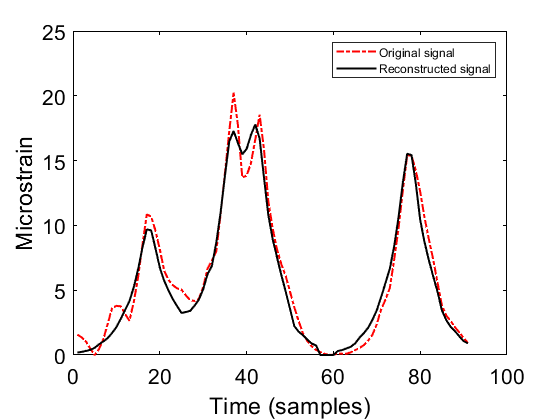

Strain_T8_L2=A_mat_T8_L2*Inf_Line_L2;


figure
plot(Test8_st40_L2,'-.r', 'Linewidth', 1.5)
% title('original signal')
hold on

plot((Strain_T8_L2),'k', 'Linewidth', 1.5)
ylabel('Microstrain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';
% title('Estimated signal')
legend('Original signal','Reconstructed signal')

## Check the IL (LANE1)

Also, lets compare the reconstructed strain response using the computed IL with the original strain response. This is for lane 1.

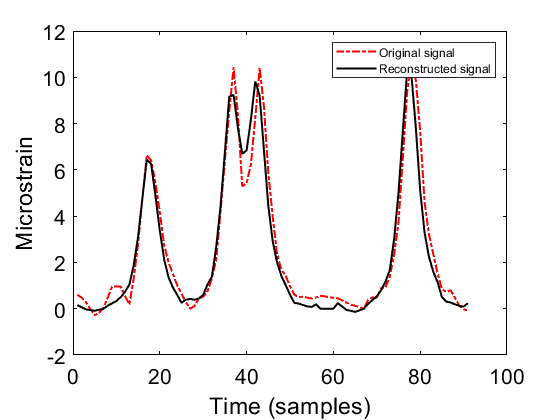

Strain_T8_L1=A_mat_T8_L1*Inf_Line_L1;


figure
plot(Test8_st40_L1,'-.r', 'Linewidth', 1.5)
% title('original signal')
hold on

plot((Strain_T8_L1),'k', 'Linewidth', 1.5)
ylabel('Microstrain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';
% title('Estimated signal')
legend('Original signal','Reconstructed signal')

The following tests are the multiple-truck events and IL1 and 2 are used for weight estimation.

## Evaluation1 (both on lane 1 )

This test is an in-one-row test with a three axle truck and 5-axle truck with the characteristics shown in chapter 3 of my dissertation. Both trucks are on lane 1 so IL on lane 1 should be used for weight estimation.

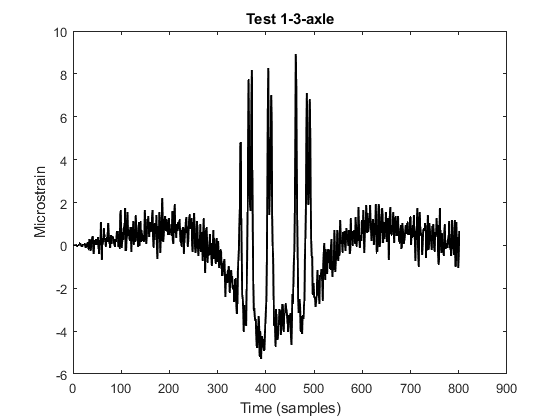

Data1 = textread('Run17.txt');


figure
plot(Data1,'k', 'Linewidth', 1.5)
title('Test 1-3-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Eva1_st40=Data1;
Eva1_st40 = wdenoise(Eva1_st40,3,'DenoisingMethod','BlockJS');


Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_Eva1] = envelope(Eva1_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Eva1_st40_TRY=Eva1_st40-low_Eva1;
  Cri_1(AA)=[abs(Eva1_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

XX(Index)

ans = 30

[up1,low_Eva1] = envelope(Eva1_st40,XX(Index),'peak');
Eva1_st40=Eva1_st40-low_Eva1;


Lets plot the modified strain:

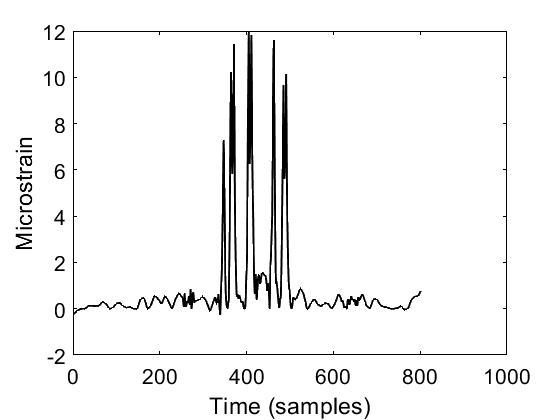


figure
plot(Eva1_st40,'k', 'Linewidth', 1.5)
hold on
% plot(low_Eva1,param_small{:});
hold off
ylabel('Microstrain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';


Eva1_st40_Threeax=Eva1_st40(447:506);
Eva1_st40_Fiveax=Eva1_st40(331:425);


Unlike the tests used for calibration, here we need two inputs, one for the 3-axle and one for the 5-axle that are shown below:

## Inputs (3-axle)

N_Eva1_Threeax=3;          %% the number of axles
v1_Eva1_Threeax=20;     %% m/s
f_Eva1_Threeax=100;         %% Hz
d1_Eva1_Threeax=0;         %% m
d2_Eva1_Threeax=4.5;      %% m
d3_Eva1_Threeax=1.31;      %% m

Weights_Eva1_Threeax=[9.1 7.1 7.1];

D1_vec_Eva1_Threeax=[d1_Eva1_Threeax d1_Eva1_Threeax+d2_Eva1_Threeax d1_Eva1_Threeax+d2_Eva1_Threeax+d3_Eva1_Threeax];

c1_Eva1_Threeax=D1_vec_Eva1_Threeax(1)*f_Eva1_Threeax/v1_Eva1_Threeax;
c2_Eva1_Threeax=D1_vec_Eva1_Threeax(2)*f_Eva1_Threeax/v1_Eva1_Threeax;
c3_Eva1_Threeax=D1_vec_Eva1_Threeax(3)*f_Eva1_Threeax/v1_Eva1_Threeax;

C1_vec_Eva1_Threeax=round([c1_Eva1_Threeax c2_Eva1_Threeax c3_Eva1_Threeax]);

[row1_Eva1_Threeax col1_Eva1_Threeax]=size(Eva1_st40_Threeax);         
k1_Eva1_Threeax=row1_Eva1_Threeax;                      %% Total number of scans


Note that I have computed A matrix but I have not used it for weight estimation. For weight estimation only Matrix B is needed.

[A_mat_Eva1_Threeax]=A_MATRIX(N_Eva1_Threeax,k1_Eva1_Threeax,C1_vec_Eva1_Threeax,Weights_Eva1_Threeax);


Again, IL1 should be used for weight estimation of both trucks since both have been on lane 1.

[B_mat_Eva1_Threeax] = B_MATRIX(N_Eva1_Threeax,k1_Eva1_Threeax,Inf_Line_L1,C1_vec_Eva1_Threeax);
Weights_estimated_Eva1_Threeax=inv((B_mat_Eva1_Threeax'*B_mat_Eva1_Threeax))*(B_mat_Eva1_Threeax'*Eva1_st40_Threeax);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva1_Threeax=Weights_estimated_Eva1_Threeax(1)+Weights_estimated_Eva1_Threeax(2)+Weights_estimated_Eva1_Threeax(3)

TotalWeight_Eva1_Threeax = 21.8210


Exact_Eva1=Weights_Eva1_Threeax(1)+Weights_Eva1_Threeax(2)+Weights_Eva1_Threeax(3)

Exact_Eva1 = 23.3000

## Inputs (5-axle)

N_Eva1_Fiveax=5;          %% the number of axles
v1_Eva1_Fiveax=20;     %% m/s
f_Eva1_Fiveax=100;        %% Hz
d1_Eva1_Fiveax=0;         %% m
d2_Eva1_Fiveax=3.4;      %% m
d3_Eva1_Fiveax=1.31;      %% m
d4_Eva1_Fiveax=6.78;     %% m
d5_Eva1_Fiveax=1.31;      %% m


Weights_Eva1_Fiveax=[6.2 8 8.2 8 8.2];

D1_vec_Eva1_Fiveax=[d1_Eva1_Fiveax d1_Eva1_Fiveax+d2_Eva1_Fiveax d1_Eva1_Fiveax+d2_Eva1_Fiveax+d3_Eva1_Fiveax d1_Eva1_Fiveax+d2_Eva1_Fiveax+d3_Eva1_Fiveax+d4_Eva1_Fiveax d1_Eva1_Fiveax+d2_Eva1_Fiveax+d3_Eva1_Fiveax+d4_Eva1_Fiveax+d5_Eva1_Fiveax];

c1_Eva1_Fiveax=D1_vec_Eva1_Fiveax(1)*f_Eva1_Fiveax/v1_Eva1_Fiveax;
c2_Eva1_Fiveax=D1_vec_Eva1_Fiveax(2)*f_Eva1_Fiveax/v1_Eva1_Fiveax;
c3_Eva1_Fiveax=D1_vec_Eva1_Fiveax(3)*f_Eva1_Fiveax/v1_Eva1_Fiveax;
c4_Eva1_Fiveax=D1_vec_Eva1_Fiveax(4)*f_Eva1_Fiveax/v1_Eva1_Fiveax;
c5_Eva1_Fiveax=D1_vec_Eva1_Fiveax(5)*f_Eva1_Fiveax/v1_Eva1_Fiveax;

C1_vec_Eva1_Fiveax=round([c1_Eva1_Fiveax c2_Eva1_Fiveax c3_Eva1_Fiveax c4_Eva1_Fiveax c5_Eva1_Fiveax]);

[row1_Eva1_Fiveax col1_Eva1_Fiveax]=size(Eva1_st40_Fiveax);
k1_Eva1_Fiveax=row1_Eva1_Fiveax;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva1_Fiveax]=A_MATRIX(N_Eva1_Fiveax,k1_Eva1_Fiveax,C1_vec_Eva1_Fiveax,Weights_Eva1_Fiveax);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva1_Fiveax] = B_MATRIX(N_Eva1_Fiveax,k1_Eva1_Fiveax,Inf_Line_L1,C1_vec_Eva1_Fiveax);
Weights_estimated_Eva1_Fiveax=inv((B_mat_Eva1_Fiveax'*B_mat_Eva1_Fiveax))*(B_mat_Eva1_Fiveax'*Eva1_st40_Fiveax);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva1_Fiveax=Weights_estimated_Eva1_Fiveax(1)+Weights_estimated_Eva1_Fiveax(2)+Weights_estimated_Eva1_Fiveax(3)+Weights_estimated_Eva1_Fiveax(4)+Weights_estimated_Eva1_Fiveax(5)

TotalWeight_Eva1_Fiveax = 38.1874

Exact_Eva1_Fiveax=Weights_Eva1_Fiveax(1)+Weights_Eva1_Fiveax(2)+Weights_Eva1_Fiveax(3)+Weights_Eva1_Fiveax(4)+Weights_Eva1_Fiveax(5)

Exact_Eva1_Fiveax = 38.6000

This test is an in-one-row test with a 3-axle truck and 5-axle truck with the characteristics shown in chapter 3 of my dissertation. Both trucks are on lane 2 so IL on lane 2 should be used for weight estimation.

## Evaluation2 (both on lane 2 )

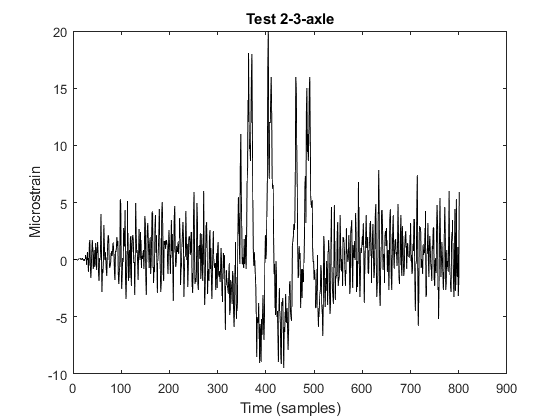

Data2 = textread('Run18.txt');
% Data1 =Data1(250:430);
figure
plot(Data2,'k', 'Linewidth', 1)
title('Test 2-3-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

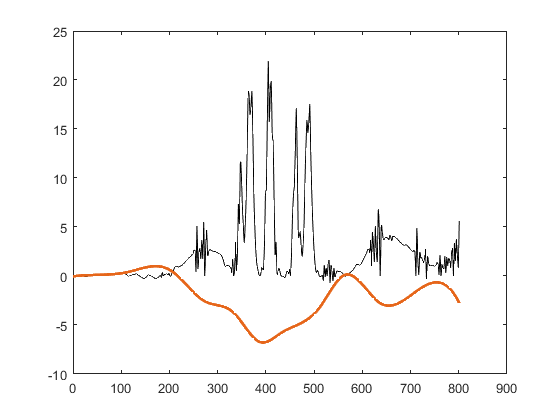

% 
Eva2_st40=Data2;
% % Eva2_st40=Eva2_st40(1:650);
Eva2_st40 = wdenoise(Eva2_st40,3,'DenoisingMethod','BlockJS');


Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_Eva2] = envelope(Eva2_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Eva2_st40_TRY=Eva2_st40-low_Eva2;
  Cri_1(AA)=[abs(Eva2_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

% XX(Index)
[up1,low_Eva2] = envelope(Eva2_st40,XX(Index),'peak');
Eva2_st40=Eva2_st40-low_Eva2;



figure
plot(Eva2_st40,'k', 'Linewidth', 1)
hold on
plot(low_Eva2,param_small{:});
hold off

Eva2_st40_Threeax=Eva2_st40(447:506);
Eva2_st40_Fiveax=Eva2_st40(331:425);



## Inputs (3-axle)

N_Eva2_Threeax=3;          %% the number of axles
v1_Eva2_Threeax=20;     %% m/s
f_Eva2_Threeax=100;         %% Hz
d1_Eva2_Threeax=0;         %% m
d2_Eva2_Threeax=4.5;      %% m
d3_Eva2_Threeax=1.31;      %% m

Weights_Eva2_Threeax=[9.1 7.1 7.1];

D1_vec_Eva2_Threeax=[d1_Eva2_Threeax d1_Eva2_Threeax+d2_Eva2_Threeax d1_Eva2_Threeax+d2_Eva2_Threeax+d3_Eva2_Threeax];

c1_Eva2_Threeax=D1_vec_Eva2_Threeax(1)*f_Eva2_Threeax/v1_Eva2_Threeax;
c2_Eva2_Threeax=D1_vec_Eva2_Threeax(2)*f_Eva2_Threeax/v1_Eva2_Threeax;
c3_Eva2_Threeax=D1_vec_Eva2_Threeax(3)*f_Eva2_Threeax/v1_Eva2_Threeax;

C1_vec_Eva2_Threeax=round([c1_Eva2_Threeax c2_Eva2_Threeax c3_Eva2_Threeax]);

[row1_Eva2_Threeax col1_Eva2_Threeax]=size(Eva2_st40_Threeax);         
k1_Eva2_Threeax=row1_Eva2_Threeax;                      %% Total number of scans

[A_mat_Eva2_Threeax]=A_MATRIX(N_Eva2_Threeax,k1_Eva2_Threeax,C1_vec_Eva2_Threeax,Weights_Eva2_Threeax);

[B_mat_Eva2_Threeax] = B_MATRIX(N_Eva2_Threeax,k1_Eva2_Threeax,Inf_Line_L2,C1_vec_Eva2_Threeax);
Weights_estimated_Eva2_Threeax=inv((B_mat_Eva2_Threeax'*B_mat_Eva2_Threeax))*(B_mat_Eva2_Threeax'*Eva2_st40_Threeax);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva2_Threeax=Weights_estimated_Eva2_Threeax(1)+Weights_estimated_Eva2_Threeax(2)+Weights_estimated_Eva2_Threeax(3)

TotalWeight_Eva2_Threeax = 22.2354


Exact_Eva2=Weights_Eva2_Threeax(1)+Weights_Eva2_Threeax(2)+Weights_Eva2_Threeax(3)

Exact_Eva2 = 23.3000

## Inputs (5-axle)

N_Eva2_Fiveax=5;          %% the number of axles
v1_Eva2_Fiveax=20;     %% m/s
f_Eva2_Fiveax=100;        %% Hz
d1_Eva2_Fiveax=0;         %% m
d2_Eva2_Fiveax=3.4;      %% m
d3_Eva2_Fiveax=1.31;      %% m
d4_Eva2_Fiveax=6.78;     %% m
d5_Eva2_Fiveax=1.31;      %% m


Weights_Eva2_Fiveax=[6.2 8 8.2 8 8.2];

D1_vec_Eva2_Fiveax=[d1_Eva2_Fiveax d1_Eva2_Fiveax+d2_Eva2_Fiveax d1_Eva2_Fiveax+d2_Eva2_Fiveax+d3_Eva2_Fiveax d1_Eva2_Fiveax+d2_Eva2_Fiveax+d3_Eva2_Fiveax+d4_Eva2_Fiveax d1_Eva2_Fiveax+d2_Eva2_Fiveax+d3_Eva2_Fiveax+d4_Eva2_Fiveax+d5_Eva2_Fiveax];

c1_Eva2_Fiveax=D1_vec_Eva2_Fiveax(1)*f_Eva2_Fiveax/v1_Eva2_Fiveax;
c2_Eva2_Fiveax=D1_vec_Eva2_Fiveax(2)*f_Eva2_Fiveax/v1_Eva2_Fiveax;
c3_Eva2_Fiveax=D1_vec_Eva2_Fiveax(3)*f_Eva2_Fiveax/v1_Eva2_Fiveax;
c4_Eva2_Fiveax=D1_vec_Eva2_Fiveax(4)*f_Eva2_Fiveax/v1_Eva2_Fiveax;
c5_Eva2_Fiveax=D1_vec_Eva2_Fiveax(5)*f_Eva2_Fiveax/v1_Eva2_Fiveax;

C1_vec_Eva2_Fiveax=round([c1_Eva2_Fiveax c2_Eva2_Fiveax c3_Eva2_Fiveax c4_Eva2_Fiveax c5_Eva2_Fiveax]);

[row1_Eva2_Fiveax col1_Eva2_Fiveax]=size(Eva2_st40_Fiveax);
k1_Eva2_Fiveax=row1_Eva2_Fiveax;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva2_Fiveax]=A_MATRIX(N_Eva2_Fiveax,k1_Eva2_Fiveax,C1_vec_Eva2_Fiveax,Weights_Eva2_Fiveax);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva2_Fiveax] = B_MATRIX(N_Eva2_Fiveax,k1_Eva2_Fiveax,Inf_Line_L2,C1_vec_Eva2_Fiveax);
Weights_estimated_Eva2_Fiveax=inv((B_mat_Eva2_Fiveax'*B_mat_Eva2_Fiveax))*(B_mat_Eva2_Fiveax'*Eva2_st40_Fiveax);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva2_Fiveax=Weights_estimated_Eva2_Fiveax(1)+Weights_estimated_Eva2_Fiveax(2)+Weights_estimated_Eva2_Fiveax(3)+Weights_estimated_Eva2_Fiveax(4)+Weights_estimated_Eva2_Fiveax(5)

TotalWeight_Eva2_Fiveax = 39.1729

Exact_Eva2_Fiveax=Weights_Eva2_Fiveax(1)+Weights_Eva2_Fiveax(2)+Weights_Eva2_Fiveax(3)+Weights_Eva2_Fiveax(4)+Weights_Eva2_Fiveax(5)

Exact_Eva2_Fiveax = 38.6000

This is a test with three 3-axle trucks in a zigzag pattern.  In this event, two trucks are on lane 1 and so IL from lane 1 should be used for weight estimation and one truck is on lane 2 and thus the IL from lane 2 should be used.

## Evaluation3 (Zigzag )

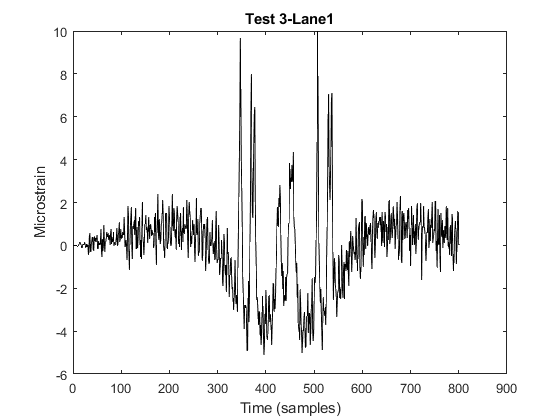

Data3 = textread('Run21_Lane1.txt');
% Data1 =Data1(250:430);
figure
plot(Data3,'k', 'Linewidth', 1)
title('Test 3-Lane1')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Eva3_st40=Data3;
% % Eva3_st40=Eva3_st40(1:650);
Eva3_st40 = wdenoise(Eva3_st40,3,'DenoisingMethod','BlockJS');
Eva3_st40(359:363)=Eva3_st40(355);


Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_Eva3] = envelope(Eva3_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Eva3_st40_TRY=Eva3_st40-low_Eva3;
  Cri_1(AA)=[abs(Eva3_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

% XX(Index)
[up1,low_Eva3] = envelope(Eva3_st40,XX(Index),'peak');
Eva3_st40=Eva3_st40-low_Eva3;


Note that it is true that the fitted curve goes up in the middle of two 3-axle trucks and again goes back down but it was observed that it still satisfies the requirements for the fitted curve (mentioned in chapter 3).

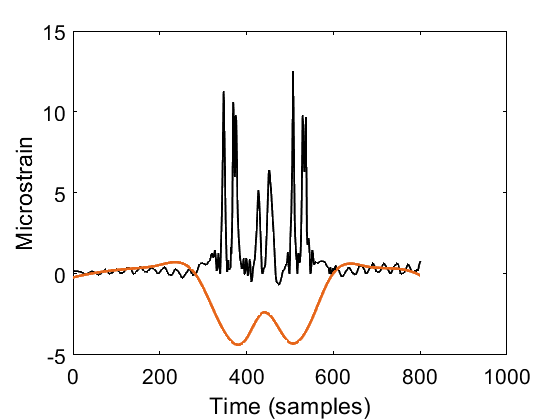


figure
plot(Eva3_st40,'k', 'Linewidth', 1.5)
hold on
plot(low_Eva3,param_small{:});
hold off
ylabel('Microstrain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';

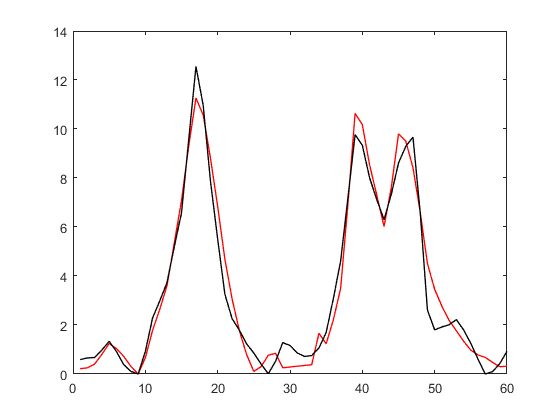


Eva3_st40_Threeax1=Eva3_st40(331:390);
Eva3_st40_Threeax3=Eva3_st40(491:550);

figure
plot(Eva3_st40_Threeax1,'r', 'Linewidth', 1)
hold on
plot(Eva3_st40_Threeax3,'k', 'Linewidth', 1)

For this case, three sets of inputs are needed for weight estimation that are shown below. Note that Matrix A is not needed for weight estimation and it is just computed as an extra/unnecessary step.

## Inputs (3-axle1)

N_Eva3_Threeax1=3;          %% the number of axles
v1_Eva3_Threeax1=20;     %% m/s
f_Eva3_Threeax1=100;         %% Hz
d1_Eva3_Threeax1=0;         %% m
d2_Eva3_Threeax1=4.5;      %% m
d3_Eva3_Threeax1=1.31;      %% m

Weights_Eva3_Threeax1=[9.1 7.1 7.1];

D1_vec_Eva3_Threeax1=[d1_Eva3_Threeax1 d1_Eva3_Threeax1+d2_Eva3_Threeax1 d1_Eva3_Threeax1+d2_Eva3_Threeax1+d3_Eva3_Threeax1];

c1_Eva3_Threeax1=D1_vec_Eva3_Threeax1(1)*f_Eva3_Threeax1/v1_Eva3_Threeax1;
c2_Eva3_Threeax1=D1_vec_Eva3_Threeax1(2)*f_Eva3_Threeax1/v1_Eva3_Threeax1;
c3_Eva3_Threeax1=D1_vec_Eva3_Threeax1(3)*f_Eva3_Threeax1/v1_Eva3_Threeax1;

C1_vec_Eva3_Threeax1=round([c1_Eva3_Threeax1 c2_Eva3_Threeax1 c3_Eva3_Threeax1]);

[row1_Eva3_Threeax1 col1_Eva3_Threeax1]=size(Eva3_st40_Threeax1);         
k1_Eva3_Threeax1=row1_Eva3_Threeax1;                      %% Total number of scans

[A_mat_Eva3_Threeax1]=A_MATRIX(N_Eva3_Threeax1,k1_Eva3_Threeax1,C1_vec_Eva3_Threeax1,Weights_Eva3_Threeax1);

[B_mat_Eva3_Threeax1] = B_MATRIX(N_Eva3_Threeax1,k1_Eva3_Threeax1,Inf_Line_L1,C1_vec_Eva3_Threeax1);
Weights_estimated_Eva3_Threeax1=inv((B_mat_Eva3_Threeax1'*B_mat_Eva3_Threeax1))*(B_mat_Eva3_Threeax1'*Eva3_st40_Threeax1);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva3_Threeax1=Weights_estimated_Eva3_Threeax1(1)+Weights_estimated_Eva3_Threeax1(2)+Weights_estimated_Eva3_Threeax1(3)

TotalWeight_Eva3_Threeax1 = 24.9104


Exact_Eva3=Weights_Eva3_Threeax1(1)+Weights_Eva3_Threeax1(2)+Weights_Eva3_Threeax1(3)

Exact_Eva3 = 23.3000

## Inputs (3-axle3)

N_Eva3_Threeax3=3;          %% the number of axles
v1_Eva3_Threeax3=20;     %% m/s
f_Eva3_Threeax3=100;         %% Hz
d1_Eva3_Threeax3=0;         %% m
d2_Eva3_Threeax3=4.5;      %% m
d3_Eva3_Threeax3=1.31;      %% m

Weights_Eva3_Threeax3=[9.1 7.1 7.1];

D1_vec_Eva3_Threeax3=[d1_Eva3_Threeax3 d1_Eva3_Threeax3+d2_Eva3_Threeax3 d1_Eva3_Threeax3+d2_Eva3_Threeax3+d3_Eva3_Threeax3];

c1_Eva3_Threeax3=D1_vec_Eva3_Threeax3(1)*f_Eva3_Threeax3/v1_Eva3_Threeax3;
c2_Eva3_Threeax3=D1_vec_Eva3_Threeax3(2)*f_Eva3_Threeax3/v1_Eva3_Threeax3;
c3_Eva3_Threeax3=D1_vec_Eva3_Threeax3(3)*f_Eva3_Threeax3/v1_Eva3_Threeax3;

C1_vec_Eva3_Threeax3=round([c1_Eva3_Threeax3 c2_Eva3_Threeax3 c3_Eva3_Threeax3]);

[row1_Eva3_Threeax3 col1_Eva3_Threeax3]=size(Eva3_st40_Threeax3);         
k1_Eva3_Threeax3=row1_Eva3_Threeax3;                      %% Total number of scans

[A_mat_Eva3_Threeax3]=A_MATRIX(N_Eva3_Threeax3,k1_Eva3_Threeax3,C1_vec_Eva3_Threeax3,Weights_Eva3_Threeax3);

[B_mat_Eva3_Threeax3] = B_MATRIX(N_Eva3_Threeax3,k1_Eva3_Threeax3,Inf_Line_L1,C1_vec_Eva3_Threeax3);
Weights_estimated_Eva3_Threeax3=inv((B_mat_Eva3_Threeax3'*B_mat_Eva3_Threeax3))*(B_mat_Eva3_Threeax3'*Eva3_st40_Threeax3);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva3_Threeax3=Weights_estimated_Eva3_Threeax3(1)+Weights_estimated_Eva3_Threeax3(2)+Weights_estimated_Eva3_Threeax3(3)

TotalWeight_Eva3_Threeax3 = 24.3180


Exact_Eva3=Weights_Eva3_Threeax1(1)+Weights_Eva3_Threeax1(2)+Weights_Eva3_Threeax1(3)

Exact_Eva3 = 23.3000

## Lane 2

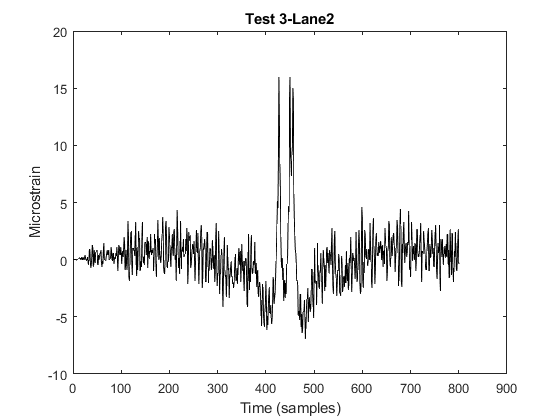

Data3 = textread('Run21_Lane2.txt');
% Data1 =Data1(250:430);
figure
plot(Data3,'k', 'Linewidth', 1)
title('Test 3-Lane2')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Eva3_st40=Data3;
% % Eva3_st40=Eva3_st40(1:650);
Eva3_st40 = wdenoise(Eva3_st40,3,'DenoisingMethod','BlockJS');
Eva3_st40(359:363)=Eva3_st40(355);


Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_Eva3] = envelope(Eva3_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Eva3_st40_TRY=Eva3_st40-low_Eva3;
  Cri_1(AA)=[abs(Eva3_st40_TRY(411,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

Index = 1


% XX(Index)
[up1,low_Eva3] = envelope(Eva3_st40,XX(Index),'peak');
Eva3_st40=Eva3_st40-low_Eva3;



Again, it was observed that the fitted curve satisfies the requirements per chapter 3 of my dissertation although it does not look pretty smooth.

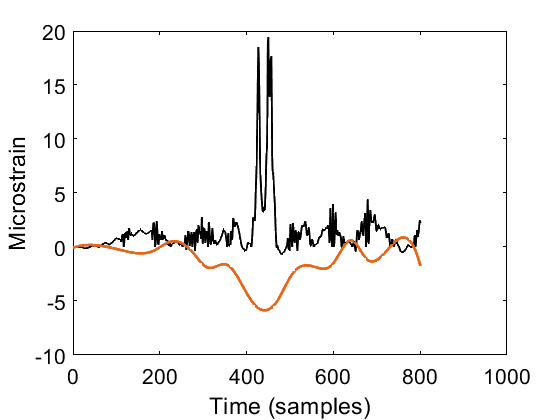

figure
plot(Eva3_st40,'k', 'Linewidth', 1.5)
hold on
plot(low_Eva3,param_small{:});
hold off
ylabel('Microstrain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';

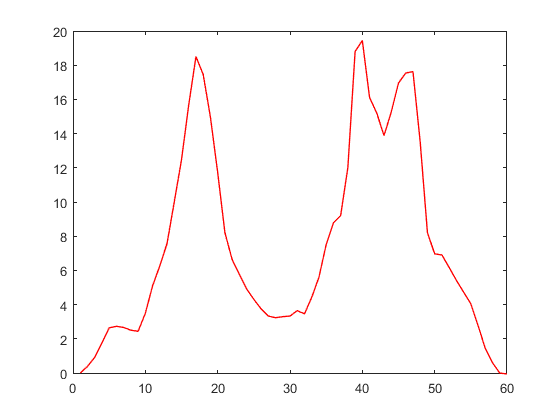

% xlim([330 560])
% ylim([-10 30])


Eva3_st40_Threeax2=Eva3_st40(411:470);


figure
plot(Eva3_st40_Threeax2,'r', 'Linewidth', 1)

## Inputs (3-axle2)

N_Eva3_Threeax2=3;          %% the number of axles
v1_Eva3_Threeax2=20;     %% m/s
f_Eva3_Threeax2=100;         %% Hz
d1_Eva3_Threeax2=0;         %% m
d2_Eva3_Threeax2=4.5;      %% m
d3_Eva3_Threeax2=1.31;      %% m

Weights_Eva3_Threeax2=[9.1 7.1 7.1];

D1_vec_Eva3_Threeax2=[d1_Eva3_Threeax2 d1_Eva3_Threeax2+d2_Eva3_Threeax2 d1_Eva3_Threeax2+d2_Eva3_Threeax2+d3_Eva3_Threeax2];

c1_Eva3_Threeax2=D1_vec_Eva3_Threeax2(1)*f_Eva3_Threeax2/v1_Eva3_Threeax2;
c2_Eva3_Threeax2=D1_vec_Eva3_Threeax2(2)*f_Eva3_Threeax2/v1_Eva3_Threeax2;
c3_Eva3_Threeax2=D1_vec_Eva3_Threeax2(3)*f_Eva3_Threeax2/v1_Eva3_Threeax2;

C1_vec_Eva3_Threeax2=round([c1_Eva3_Threeax2 c2_Eva3_Threeax2 c3_Eva3_Threeax2]);

[row1_Eva3_Threeax2 col1_Eva3_Threeax2]=size(Eva3_st40_Threeax2);         
k1_Eva3_Threeax2=row1_Eva3_Threeax2;                      %% Total number of scans

[A_mat_Eva3_Threeax2]=A_MATRIX(N_Eva3_Threeax2,k1_Eva3_Threeax2,C1_vec_Eva3_Threeax2,Weights_Eva3_Threeax2);

[B_mat_Eva3_Threeax2] = B_MATRIX(N_Eva3_Threeax2,k1_Eva3_Threeax2,Inf_Line_L2,C1_vec_Eva3_Threeax2);
Weights_estimated_Eva3_Threeax2=inv((B_mat_Eva3_Threeax2'*B_mat_Eva3_Threeax2))*(B_mat_Eva3_Threeax2'*Eva3_st40_Threeax2);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva3_Threeax2=Weights_estimated_Eva3_Threeax2(1)+Weights_estimated_Eva3_Threeax2(2)+Weights_estimated_Eva3_Threeax2(3)

TotalWeight_Eva3_Threeax2 = 23.8333


Exact_Eva3=Weights_Eva3_Threeax1(1)+Weights_Eva3_Threeax1(2)+Weights_Eva3_Threeax1(3)

Exact_Eva3 = 23.3000

This is a test with three 3-axle trucks in a zigzag pattern.  In this event, two trucks are on lane 2 and so IL from lane 2 should be used for weight estimation and one truck is on lane 1 and thus the IL from lane 1 should be used.

## Evaluation5 (Zigzag )

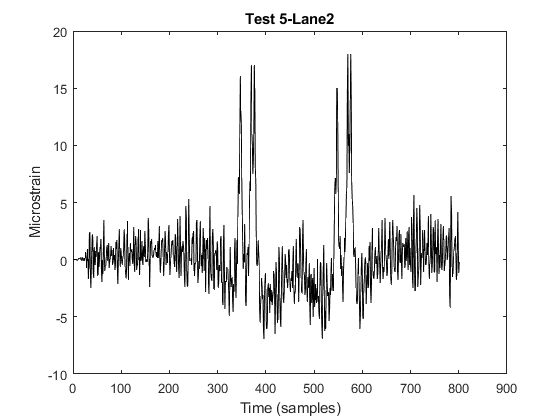

Data5 = textread('Run23_L2.txt');
% Data1 =Data1(250:430);
figure
plot(Data5,'k', 'Linewidth', 1)
title('Test 5-Lane2')
xlabel('Time (samples)')
ylabel('Microstrain')

Eva5_st40=Data5;
% % Eva5_st40=Eva5_st40(1:650);
Eva5_st40 = wdenoise(Eva5_st40,3,'DenoisingMethod','BlockJS');
Eva5_st40(229:252)=Eva5_st40(229);


Cri_1=[];
AA=1;
XX=[40 45 50];
for BB=1:length(XX)
  [up1,low_Eva5] = envelope(Eva5_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Eva5_st40_TRY=Eva5_st40-low_Eva5;
  Cri_1(AA)=[abs(Eva5_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

Index = 1


% XX(Index)
[up1,low_Eva5] = envelope(Eva5_st40,XX(Index),'peak');
Eva5_st40=Eva5_st40-low_Eva5;


Note that it is true that the fitted curve goes up in the middle of two 3-axle trucks and again goes back down but it was observed that it still satisfies the requirements for the fitted curve (mentioned in chapter 3).

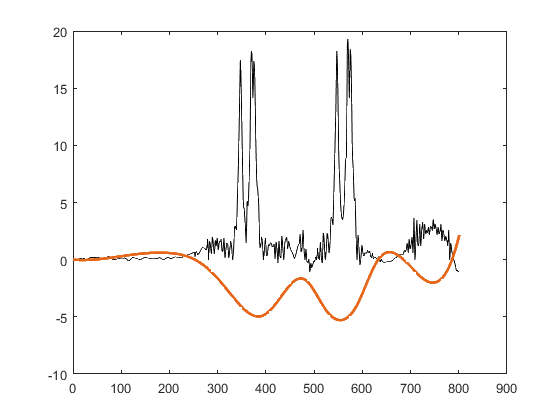


figure
plot(Eva5_st40,'k', 'Linewidth', 1)
hold on
plot(low_Eva5,param_small{:});
hold off

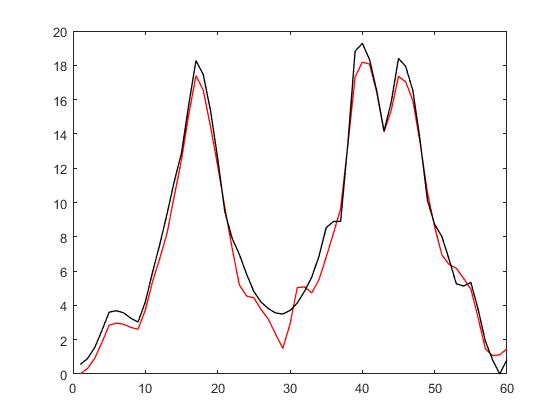

Eva5_st40_Threeax1=Eva5_st40(331:390);
Eva5_st40_Threeax3=Eva5_st40(531:590);

figure
plot(Eva5_st40_Threeax1,'r', 'Linewidth', 1)
hold on
plot(Eva5_st40_Threeax3,'k', 'Linewidth', 1)

Again, three sets of inputs are needed (one for each truck):

## Inputs (3-axle1)

N_Eva5_Threeax1=3;          %% the number of axles
v1_Eva5_Threeax1=20;     %% m/s
f_Eva5_Threeax1=100;         %% Hz
d1_Eva5_Threeax1=0;         %% m
d2_Eva5_Threeax1=4.5;      %% m
d3_Eva5_Threeax1=1.31;      %% m

Weights_Eva5_Threeax1=[9.1 7.1 7.1];

D1_vec_Eva5_Threeax1=[d1_Eva5_Threeax1 d1_Eva5_Threeax1+d2_Eva5_Threeax1 d1_Eva5_Threeax1+d2_Eva5_Threeax1+d3_Eva5_Threeax1];

c1_Eva5_Threeax1=D1_vec_Eva5_Threeax1(1)*f_Eva5_Threeax1/v1_Eva5_Threeax1;
c2_Eva5_Threeax1=D1_vec_Eva5_Threeax1(2)*f_Eva5_Threeax1/v1_Eva5_Threeax1;
c3_Eva5_Threeax1=D1_vec_Eva5_Threeax1(3)*f_Eva5_Threeax1/v1_Eva5_Threeax1;

C1_vec_Eva5_Threeax1=round([c1_Eva5_Threeax1 c2_Eva5_Threeax1 c3_Eva5_Threeax1]);

[row1_Eva5_Threeax1 col1_Eva5_Threeax1]=size(Eva5_st40_Threeax1);         
k1_Eva5_Threeax1=row1_Eva5_Threeax1;                      %% Total number of scans

[A_mat_Eva5_Threeax1]=A_MATRIX(N_Eva5_Threeax1,k1_Eva5_Threeax1,C1_vec_Eva5_Threeax1,Weights_Eva5_Threeax1);

[B_mat_Eva5_Threeax1] = B_MATRIX(N_Eva5_Threeax1,k1_Eva5_Threeax1,Inf_Line_L2,C1_vec_Eva5_Threeax1);
Weights_estimated_Eva5_Threeax1=inv((B_mat_Eva5_Threeax1'*B_mat_Eva5_Threeax1))*(B_mat_Eva5_Threeax1'*Eva5_st40_Threeax1);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva5_Threeax1=Weights_estimated_Eva5_Threeax1(1)+Weights_estimated_Eva5_Threeax1(2)+Weights_estimated_Eva5_Threeax1(3)

TotalWeight_Eva5_Threeax1 = 23.9814


Exact_Eva5=Weights_Eva5_Threeax1(1)+Weights_Eva5_Threeax1(2)+Weights_Eva5_Threeax1(3)

Exact_Eva5 = 23.3000

## Inputs (3-axle3)

N_Eva5_Threeax3=3;          %% the number of axles
v1_Eva5_Threeax3=20;     %% m/s
f_Eva5_Threeax3=100;         %% Hz
d1_Eva5_Threeax3=0;         %% m
d2_Eva5_Threeax3=4.5;      %% m
d3_Eva5_Threeax3=1.31;      %% m

Weights_Eva5_Threeax3=[9.1 7.1 7.1];

D1_vec_Eva5_Threeax3=[d1_Eva5_Threeax3 d1_Eva5_Threeax3+d2_Eva5_Threeax3 d1_Eva5_Threeax3+d2_Eva5_Threeax3+d3_Eva5_Threeax3];

c1_Eva5_Threeax3=D1_vec_Eva5_Threeax3(1)*f_Eva5_Threeax3/v1_Eva5_Threeax3;
c2_Eva5_Threeax3=D1_vec_Eva5_Threeax3(2)*f_Eva5_Threeax3/v1_Eva5_Threeax3;
c3_Eva5_Threeax3=D1_vec_Eva5_Threeax3(3)*f_Eva5_Threeax3/v1_Eva5_Threeax3;

C1_vec_Eva5_Threeax3=round([c1_Eva5_Threeax3 c2_Eva5_Threeax3 c3_Eva5_Threeax3]);

[row1_Eva5_Threeax3 col1_Eva5_Threeax3]=size(Eva5_st40_Threeax3);         
k1_Eva5_Threeax3=row1_Eva5_Threeax3;                      %% Total number of scans

[A_mat_Eva5_Threeax3]=A_MATRIX(N_Eva5_Threeax3,k1_Eva5_Threeax3,C1_vec_Eva5_Threeax3,Weights_Eva5_Threeax3);

[B_mat_Eva5_Threeax3] = B_MATRIX(N_Eva5_Threeax3,k1_Eva5_Threeax3,Inf_Line_L2,C1_vec_Eva5_Threeax3);
Weights_estimated_Eva5_Threeax3=inv((B_mat_Eva5_Threeax3'*B_mat_Eva5_Threeax3))*(B_mat_Eva5_Threeax3'*Eva5_st40_Threeax3);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva5_Threeax3=Weights_estimated_Eva5_Threeax3(1)+Weights_estimated_Eva5_Threeax3(2)+Weights_estimated_Eva5_Threeax3(3)

TotalWeight_Eva5_Threeax3 = 25.1577


Exact_Eva5=Weights_Eva5_Threeax1(1)+Weights_Eva5_Threeax1(2)+Weights_Eva5_Threeax1(3)

Exact_Eva5 = 23.3000

## Lane 2

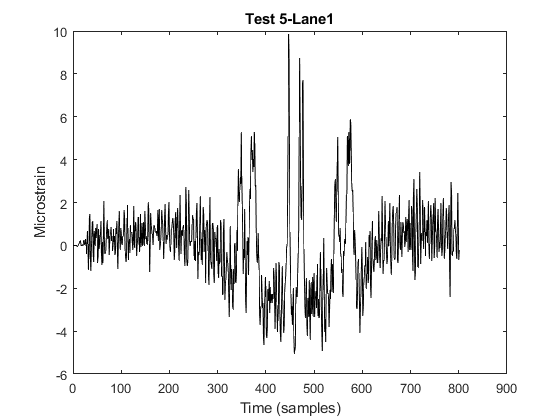

Data5 = textread('Run23_L1.txt');
% Data1 =Data1(250:430);
figure
plot(Data5,'k', 'Linewidth', 1)
title('Test 5-Lane1')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Eva5_st40=Data5;
% % Eva5_st40=Eva5_st40(1:650);
Eva5_st40 = wdenoise(Eva5_st40,3,'DenoisingMethod','BlockJS');
Eva5_st40(457:463)=Eva5_st40(457);


Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_Eva5] = envelope(Eva5_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Eva5_st40_TRY=Eva5_st40-low_Eva5;
  Cri_1(AA)=[abs(Eva5_st40_TRY(431,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

Index = 1

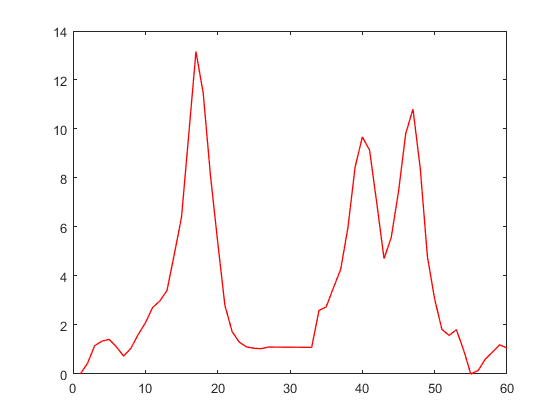


% XX(Index)
[up1,low_Eva5] = envelope(Eva5_st40,XX(Index),'peak');
Eva5_st40=Eva5_st40-low_Eva5;

Eva5_st40_Threeax2=Eva5_st40(431:490);


figure
plot(Eva5_st40_Threeax2,'r', 'Linewidth', 1)

## Inputs (3-axle2)

N_Eva5_Threeax2=3;          %% the number of axles
v1_Eva5_Threeax2=20;     %% m/s
f_Eva5_Threeax2=100;         %% Hz
d1_Eva5_Threeax2=0;         %% m
d2_Eva5_Threeax2=4.5;      %% m
d3_Eva5_Threeax2=1.31;      %% m

Weights_Eva5_Threeax2=[9.1 7.1 7.1];

D1_vec_Eva5_Threeax2=[d1_Eva5_Threeax2 d1_Eva5_Threeax2+d2_Eva5_Threeax2 d1_Eva5_Threeax2+d2_Eva5_Threeax2+d3_Eva5_Threeax2];

c1_Eva5_Threeax2=D1_vec_Eva5_Threeax2(1)*f_Eva5_Threeax2/v1_Eva5_Threeax2;
c2_Eva5_Threeax2=D1_vec_Eva5_Threeax2(2)*f_Eva5_Threeax2/v1_Eva5_Threeax2;
c3_Eva5_Threeax2=D1_vec_Eva5_Threeax2(3)*f_Eva5_Threeax2/v1_Eva5_Threeax2;

C1_vec_Eva5_Threeax2=round([c1_Eva5_Threeax2 c2_Eva5_Threeax2 c3_Eva5_Threeax2]);

[row1_Eva5_Threeax2 col1_Eva5_Threeax2]=size(Eva5_st40_Threeax2);         
k1_Eva5_Threeax2=row1_Eva5_Threeax2;                      %% Total number of scans

[A_mat_Eva5_Threeax2]=A_MATRIX(N_Eva5_Threeax2,k1_Eva5_Threeax2,C1_vec_Eva5_Threeax2,Weights_Eva5_Threeax2);

[B_mat_Eva5_Threeax2] = B_MATRIX(N_Eva5_Threeax2,k1_Eva5_Threeax2,Inf_Line_L1,C1_vec_Eva5_Threeax2);
Weights_estimated_Eva5_Threeax2=inv((B_mat_Eva5_Threeax2'*B_mat_Eva5_Threeax2))*(B_mat_Eva5_Threeax2'*Eva5_st40_Threeax2);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva5_Threeax2=Weights_estimated_Eva5_Threeax2(1)+Weights_estimated_Eva5_Threeax2(2)+Weights_estimated_Eva5_Threeax2(3)

TotalWeight_Eva5_Threeax2 = 24.6693


Exact_Eva5=Weights_Eva5_Threeax1(1)+Weights_Eva5_Threeax1(2)+Weights_Eva5_Threeax1(3)

Exact_Eva5 = 23.3000

This test is a side-by-side event with 5-axle truck on the first lane and a 3-axle on the second lane. 

## Evaluation6 (Side-by-side)

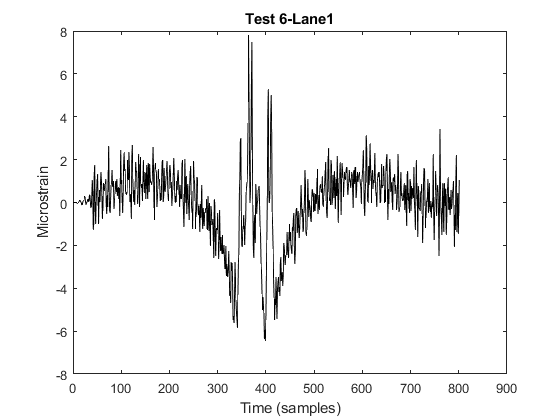

Data6 = textread('Run20_2_L1.txt');


figure
plot(Data6,'k', 'Linewidth', 1)
title('Test 6-Lane1')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Eva6_st40=Data6;
% % Eva6_st40=Eva6_st40(1:650);
Eva6_st40 = wdenoise(Eva6_st40,3,'DenoisingMethod','BlockJS');
% Eva6_st40(359:363)=Eva6_st40(355);


Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_Eva6] = envelope(Eva6_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Eva6_st40_TRY=Eva6_st40-low_Eva6;
  Cri_1(AA)=[abs(Eva6_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

% XX(Index)
[up1,low_Eva6] = envelope(Eva6_st40,XX(Index),'peak');
Eva6_st40=Eva6_st40-low_Eva6;



Now lets plot the modified strain response. This is the strain response of the 5-axle truck with the corruption (from the adjacent 3-axle truck) included.

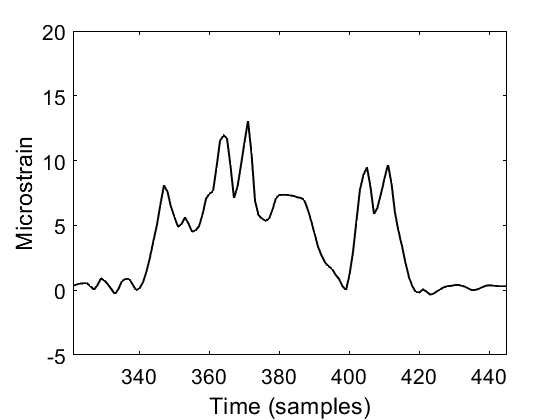

figure
plot(Eva6_st40,'k', 'Linewidth', 1.5)
hold on
% plot(low_Eva6,param_small{:});
% hold off
ylabel('Microstrain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';
xlim([321 445])
ylim([-5 20])

Here the corruptions are manually found and zeroed. The procedure is similar to what is explained in the third chapter of my dissertation but not exactly the same. The slight difference will not make a significant change to the results accuracy and can be still valid.


Eva6_st40(374:399)=0;
Eva6_st40(351:361)=0;


Now, we plot the modified strain when the corruption is removed.

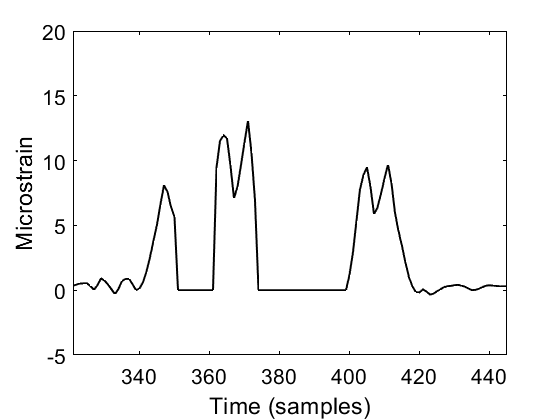

figure
plot(Eva6_st40,'k', 'Linewidth', 1.5)
hold on
% plot(low_Eva6,param_small{:});
% hold off
ylabel('Microstrain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';
xlim([321 445])
ylim([-5 20])




Eva6_st40_Fiveax=Eva6_st40(331:425);

% figure
% plot(Eva6_st40_Fiveax,'r', 'Linewidth', 1)


## Inputs (5-axle)

N_Eva6_Fiveax=5;          %% the number of axles
v1_Eva6_Fiveax=20;     %% m/s
f_Eva6_Fiveax=100;        %% Hz
d1_Eva6_Fiveax=0;         %% m
d2_Eva6_Fiveax=3.4;      %% m
d3_Eva6_Fiveax=1.31;      %% m
d4_Eva6_Fiveax=6.78;     %% m
d5_Eva6_Fiveax=1.31;      %% m


Weights_Eva6_Fiveax=[6.2 8 8.2 8 8.2];

D1_vec_Eva6_Fiveax=[d1_Eva6_Fiveax d1_Eva6_Fiveax+d2_Eva6_Fiveax d1_Eva6_Fiveax+d2_Eva6_Fiveax+d3_Eva6_Fiveax d1_Eva6_Fiveax+d2_Eva6_Fiveax+d3_Eva6_Fiveax+d4_Eva6_Fiveax d1_Eva6_Fiveax+d2_Eva6_Fiveax+d3_Eva6_Fiveax+d4_Eva6_Fiveax+d5_Eva6_Fiveax];

c1_Eva6_Fiveax=D1_vec_Eva6_Fiveax(1)*f_Eva6_Fiveax/v1_Eva6_Fiveax;
c2_Eva6_Fiveax=D1_vec_Eva6_Fiveax(2)*f_Eva6_Fiveax/v1_Eva6_Fiveax;
c3_Eva6_Fiveax=D1_vec_Eva6_Fiveax(3)*f_Eva6_Fiveax/v1_Eva6_Fiveax;
c4_Eva6_Fiveax=D1_vec_Eva6_Fiveax(4)*f_Eva6_Fiveax/v1_Eva6_Fiveax;
c5_Eva6_Fiveax=D1_vec_Eva6_Fiveax(5)*f_Eva6_Fiveax/v1_Eva6_Fiveax;

C1_vec_Eva6_Fiveax=round([c1_Eva6_Fiveax c2_Eva6_Fiveax c3_Eva6_Fiveax c4_Eva6_Fiveax c5_Eva6_Fiveax]);

[row1_Eva6_Fiveax col1_Eva6_Fiveax]=size(Eva6_st40_Fiveax);
k1_Eva6_Fiveax=row1_Eva6_Fiveax;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva6_Fiveax]=A_MATRIX(N_Eva6_Fiveax,k1_Eva6_Fiveax,C1_vec_Eva6_Fiveax,Weights_Eva6_Fiveax);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva6_Fiveax] = B_MATRIX(N_Eva6_Fiveax,k1_Eva6_Fiveax,Inf_Line_L1,C1_vec_Eva6_Fiveax);
Weights_estimated_Eva6_Fiveax=inv((B_mat_Eva6_Fiveax'*B_mat_Eva6_Fiveax))*(B_mat_Eva6_Fiveax'*Eva6_st40_Fiveax);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva6_Fiveax=Weights_estimated_Eva6_Fiveax(1)+Weights_estimated_Eva6_Fiveax(2)+Weights_estimated_Eva6_Fiveax(3)+Weights_estimated_Eva6_Fiveax(4)+Weights_estimated_Eva6_Fiveax(5)

TotalWeight_Eva6_Fiveax = 39.5341

Exact_Eva6_Fiveax=Weights_Eva6_Fiveax(1)+Weights_Eva6_Fiveax(2)+Weights_Eva6_Fiveax(3)+Weights_Eva6_Fiveax(4)+Weights_Eva6_Fiveax(5)

Exact_Eva6_Fiveax = 38.6000

This is now the strain response from the 3-axle truck on the second lane.

## Lane 2 (3-axle truck)

Data6 = textread('Run20_L2.txt');

Eva6_st40=Data6;


Eva6_st40 = wdenoise(Eva6_st40,3,'DenoisingMethod','BlockJS');



Cri_1=[];
AA=1;
XX=[40 45 50];
for BB=1:length(XX)
  [up1,low_Eva6] = envelope(Eva6_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Eva6_st40_TRY=Eva6_st40-low_Eva6;
  Cri_1(AA)=[abs(Eva6_st40_TRY(347,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

Index = 1


% XX(Index)
[up1,low_Eva6] = envelope(Eva6_st40,XX(Index),'peak');
Eva6_st40=Eva6_st40-low_Eva6;






Eva6_st40_Threeax=Eva6_st40(347:406);


% figure
% plot(Eva6_st40_Threeax,'r', 'Linewidth', 1)

## Inputs (3-axle)

N_Eva6_Threeax=3;          %% the number of axles
v1_Eva6_Threeax=20;     %% m/s
f_Eva6_Threeax=100;         %% Hz
d1_Eva6_Threeax=0;         %% m
d2_Eva6_Threeax=4.5;      %% m
d3_Eva6_Threeax=1.31;      %% m

Weights_Eva6_Threeax=[9.1 7.1 7.1];

D1_vec_Eva6_Threeax=[d1_Eva6_Threeax d1_Eva6_Threeax+d2_Eva6_Threeax d1_Eva6_Threeax+d2_Eva6_Threeax+d3_Eva6_Threeax];

c1_Eva6_Threeax=D1_vec_Eva6_Threeax(1)*f_Eva6_Threeax/v1_Eva6_Threeax;
c2_Eva6_Threeax=D1_vec_Eva6_Threeax(2)*f_Eva6_Threeax/v1_Eva6_Threeax;
c3_Eva6_Threeax=D1_vec_Eva6_Threeax(3)*f_Eva6_Threeax/v1_Eva6_Threeax;

C1_vec_Eva6_Threeax=round([c1_Eva6_Threeax c2_Eva6_Threeax c3_Eva6_Threeax]);

[row1_Eva6_Threeax col1_Eva6_Threeax]=size(Eva6_st40_Threeax);         
k1_Eva6_Threeax=row1_Eva6_Threeax;                      %% Total number of scans

[A_mat_Eva6_Threeax]=A_MATRIX(N_Eva6_Threeax,k1_Eva6_Threeax,C1_vec_Eva6_Threeax,Weights_Eva6_Threeax);

[B_mat_Eva6_Threeax] = B_MATRIX(N_Eva6_Threeax,k1_Eva6_Threeax,Inf_Line_L2,C1_vec_Eva6_Threeax);
Weights_estimated_Eva6_Threeax=inv((B_mat_Eva6_Threeax'*B_mat_Eva6_Threeax))*(B_mat_Eva6_Threeax'*Eva6_st40_Threeax);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva6_Threeax=Weights_estimated_Eva6_Threeax(1)+Weights_estimated_Eva6_Threeax(2)+Weights_estimated_Eva6_Threeax(3)

TotalWeight_Eva6_Threeax = 20.8288


Exact_Eva6_Threeax=Weights_Eva6_Threeax(1)+Weights_Eva6_Threeax(2)+Weights_Eva6_Threeax(3)

Exact_Eva6_Threeax = 23.3000

This event is the most complex traffic pattern with two 3-axle trucks on the first lane and a 5-axle on the second lane and two light-weight vehicles on the third lane. We will only compute the weights of the trucks. The procedure will be pretty similar to other zigzag patterns since it was observed that the light-weight vehicles do not have a significant effect on the strain response.

## Evaluation7 (Zigzag+light weights)

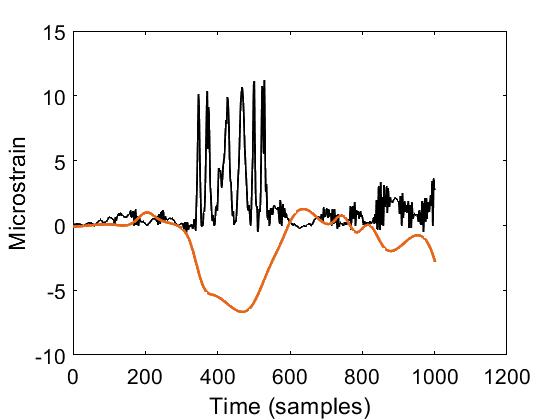

Data7 = textread('Run22_L1.txt');

% 
Eva7_st40=Data7;

Eva7_st40 = wdenoise(Eva7_st40,3,'DenoisingMethod','BlockJS');



Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_Eva7] = envelope(Eva7_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Eva7_st40_TRY=Eva7_st40-low_Eva7;
  Cri_1(AA)=[abs(Eva7_st40_TRY(331,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

% XX(Index)
[up1,low_Eva7] = envelope(Eva7_st40,XX(Index),'peak');
Eva7_st40=Eva7_st40-low_Eva7;




figure
plot(Eva7_st40,'k', 'Linewidth', 1.5)
hold on
plot(low_Eva7,param_small{:});
hold off
ylabel('Microstrain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';

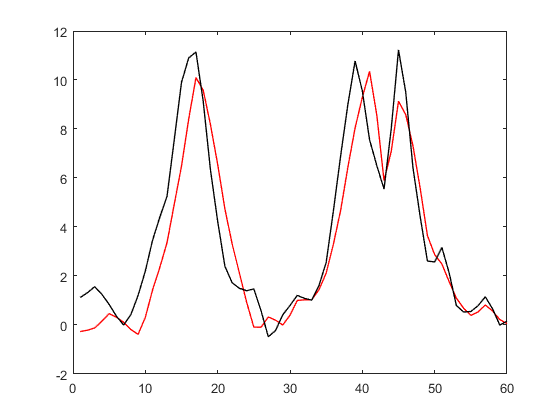

% xlim([321 551])
% ylim([-5 17])


Eva7_st40_Threeax1=Eva7_st40(331:390);
Eva7_st40_Threeax3=Eva7_st40(485:544);

figure
plot(Eva7_st40_Threeax1,'r', 'Linewidth', 1)
hold on
plot(Eva7_st40_Threeax3,'k', 'Linewidth', 1)

## Inputs (3-axle1)

N_Eva7_Threeax1=3;          %% the number of axles
v1_Eva7_Threeax1=20;     %% m/s
f_Eva7_Threeax1=100;         %% Hz
d1_Eva7_Threeax1=0;         %% m
d2_Eva7_Threeax1=4.5;      %% m
d3_Eva7_Threeax1=1.31;      %% m

Weights_Eva7_Threeax1=[9.1 7.1 7.1];

D1_vec_Eva7_Threeax1=[d1_Eva7_Threeax1 d1_Eva7_Threeax1+d2_Eva7_Threeax1 d1_Eva7_Threeax1+d2_Eva7_Threeax1+d3_Eva7_Threeax1];

c1_Eva7_Threeax1=D1_vec_Eva7_Threeax1(1)*f_Eva7_Threeax1/v1_Eva7_Threeax1;
c2_Eva7_Threeax1=D1_vec_Eva7_Threeax1(2)*f_Eva7_Threeax1/v1_Eva7_Threeax1;
c3_Eva7_Threeax1=D1_vec_Eva7_Threeax1(3)*f_Eva7_Threeax1/v1_Eva7_Threeax1;

C1_vec_Eva7_Threeax1=round([c1_Eva7_Threeax1 c2_Eva7_Threeax1 c3_Eva7_Threeax1]);

[row1_Eva7_Threeax1 col1_Eva7_Threeax1]=size(Eva7_st40_Threeax1);         
k1_Eva7_Threeax1=row1_Eva7_Threeax1;                      %% Total number of scans

[A_mat_Eva7_Threeax1]=A_MATRIX(N_Eva7_Threeax1,k1_Eva7_Threeax1,C1_vec_Eva7_Threeax1,Weights_Eva7_Threeax1);

[B_mat_Eva7_Threeax1] = B_MATRIX(N_Eva7_Threeax1,k1_Eva7_Threeax1,Inf_Line_L1,C1_vec_Eva7_Threeax1);
Weights_estimated_Eva7_Threeax1=inv((B_mat_Eva7_Threeax1'*B_mat_Eva7_Threeax1))*(B_mat_Eva7_Threeax1'*Eva7_st40_Threeax1);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva7_Threeax1=Weights_estimated_Eva7_Threeax1(1)+Weights_estimated_Eva7_Threeax1(2)+Weights_estimated_Eva7_Threeax1(3)

TotalWeight_Eva7_Threeax1 = 23.3499


Exact_Eva7=Weights_Eva7_Threeax1(1)+Weights_Eva7_Threeax1(2)+Weights_Eva7_Threeax1(3)

Exact_Eva7 = 23.3000

## Inputs (3-axle3)

N_Eva7_Threeax3=3;          %% the number of axles
v1_Eva7_Threeax3=20;     %% m/s
f_Eva7_Threeax3=100;         %% Hz
d1_Eva7_Threeax3=0;         %% m
d2_Eva7_Threeax3=4.5;      %% m
d3_Eva7_Threeax3=1.31;      %% m

Weights_Eva7_Threeax3=[9.1 7.1 7.1];

D1_vec_Eva7_Threeax3=[d1_Eva7_Threeax3 d1_Eva7_Threeax3+d2_Eva7_Threeax3 d1_Eva7_Threeax3+d2_Eva7_Threeax3+d3_Eva7_Threeax3];

c1_Eva7_Threeax3=D1_vec_Eva7_Threeax3(1)*f_Eva7_Threeax3/v1_Eva7_Threeax3;
c2_Eva7_Threeax3=D1_vec_Eva7_Threeax3(2)*f_Eva7_Threeax3/v1_Eva7_Threeax3;
c3_Eva7_Threeax3=D1_vec_Eva7_Threeax3(3)*f_Eva7_Threeax3/v1_Eva7_Threeax3;

C1_vec_Eva7_Threeax3=round([c1_Eva7_Threeax3 c2_Eva7_Threeax3 c3_Eva7_Threeax3]);

[row1_Eva7_Threeax3 col1_Eva7_Threeax3]=size(Eva7_st40_Threeax3);         
k1_Eva7_Threeax3=row1_Eva7_Threeax3;                      %% Total number of scans

[A_mat_Eva7_Threeax3]=A_MATRIX(N_Eva7_Threeax3,k1_Eva7_Threeax3,C1_vec_Eva7_Threeax3,Weights_Eva7_Threeax3);

[B_mat_Eva7_Threeax3] = B_MATRIX(N_Eva7_Threeax3,k1_Eva7_Threeax3,Inf_Line_L1,C1_vec_Eva7_Threeax3);
Weights_estimated_Eva7_Threeax3=inv((B_mat_Eva7_Threeax3'*B_mat_Eva7_Threeax3))*(B_mat_Eva7_Threeax3'*Eva7_st40_Threeax3);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva7_Threeax3=Weights_estimated_Eva7_Threeax3(1)+Weights_estimated_Eva7_Threeax3(2)+Weights_estimated_Eva7_Threeax3(3)

TotalWeight_Eva7_Threeax3 = 23.9907


Exact_Eva7=Weights_Eva7_Threeax1(1)+Weights_Eva7_Threeax1(2)+Weights_Eva7_Threeax1(3)

Exact_Eva7 = 23.3000

## Lane 2

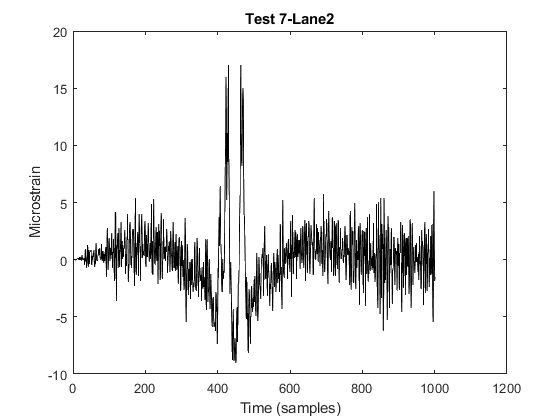

Data7 = textread('Run22_L2.txt');
% Data1 =Data1(250:430);
figure
plot(Data7,'k', 'Linewidth', 1)
title('Test 7-Lane2')
xlabel('Time (samples)')
ylabel('Microstrain')

% 
Eva7_st40=Data7;
% % Eva7_st40=Eva7_st40(1:650);
Eva7_st40 = wdenoise(Eva7_st40,3,'DenoisingMethod','BlockJS');
Eva7_st40(359:363)=Eva7_st40(355);


Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_Eva7] = envelope(Eva7_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Eva7_st40_TRY=Eva7_st40-low_Eva7;
  Cri_1(AA)=[abs(Eva7_st40_TRY(391,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end

Index = 1

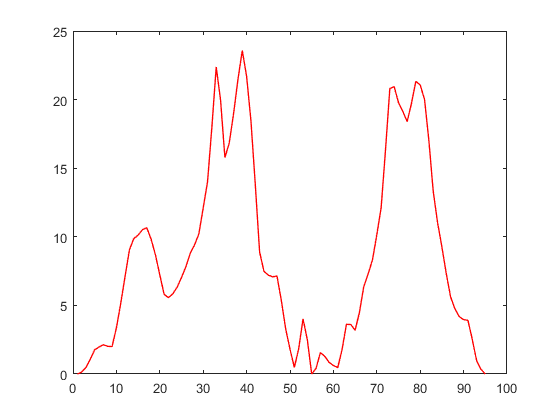


% XX(Index)
[up1,low_Eva7] = envelope(Eva7_st40,XX(Index),'peak');
Eva7_st40=Eva7_st40-low_Eva7;

% xlim([321 551])
% ylim([-10 35])


Eva7_st40_Fiveax=Eva7_st40(391:485);


figure
plot(Eva7_st40_Fiveax,'r', 'Linewidth', 1)

## Inputs (5-axle)

N_Eva7_Fiveax=5;          %% the number of axles
v1_Eva7_Fiveax=20;     %% m/s
f_Eva7_Fiveax=100;        %% Hz
d1_Eva7_Fiveax=0;         %% m
d2_Eva7_Fiveax=3.4;      %% m
d3_Eva7_Fiveax=1.31;      %% m
d4_Eva7_Fiveax=6.78;     %% m
d5_Eva7_Fiveax=1.31;      %% m


Weights_Eva7_Fiveax=[6.2 8 8.2 8 8.2];

D1_vec_Eva7_Fiveax=[d1_Eva7_Fiveax d1_Eva7_Fiveax+d2_Eva7_Fiveax d1_Eva7_Fiveax+d2_Eva7_Fiveax+d3_Eva7_Fiveax d1_Eva7_Fiveax+d2_Eva7_Fiveax+d3_Eva7_Fiveax+d4_Eva7_Fiveax d1_Eva7_Fiveax+d2_Eva7_Fiveax+d3_Eva7_Fiveax+d4_Eva7_Fiveax+d5_Eva7_Fiveax];

c1_Eva7_Fiveax=D1_vec_Eva7_Fiveax(1)*f_Eva7_Fiveax/v1_Eva7_Fiveax;
c2_Eva7_Fiveax=D1_vec_Eva7_Fiveax(2)*f_Eva7_Fiveax/v1_Eva7_Fiveax;
c3_Eva7_Fiveax=D1_vec_Eva7_Fiveax(3)*f_Eva7_Fiveax/v1_Eva7_Fiveax;
c4_Eva7_Fiveax=D1_vec_Eva7_Fiveax(4)*f_Eva7_Fiveax/v1_Eva7_Fiveax;
c5_Eva7_Fiveax=D1_vec_Eva7_Fiveax(5)*f_Eva7_Fiveax/v1_Eva7_Fiveax;

C1_vec_Eva7_Fiveax=round([c1_Eva7_Fiveax c2_Eva7_Fiveax c3_Eva7_Fiveax c4_Eva7_Fiveax c5_Eva7_Fiveax]);

[row1_Eva7_Fiveax col1_Eva7_Fiveax]=size(Eva7_st40_Fiveax);
k1_Eva7_Fiveax=row1_Eva7_Fiveax;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva7_Fiveax]=A_MATRIX(N_Eva7_Fiveax,k1_Eva7_Fiveax,C1_vec_Eva7_Fiveax,Weights_Eva7_Fiveax);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva7_Fiveax] = B_MATRIX(N_Eva7_Fiveax,k1_Eva7_Fiveax,Inf_Line_L2,C1_vec_Eva7_Fiveax);
Weights_estimated_Eva7_Fiveax=inv((B_mat_Eva7_Fiveax'*B_mat_Eva7_Fiveax))*(B_mat_Eva7_Fiveax'*Eva7_st40_Fiveax);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva7_Fiveax=Weights_estimated_Eva7_Fiveax(1)+Weights_estimated_Eva7_Fiveax(2)+Weights_estimated_Eva7_Fiveax(3)+Weights_estimated_Eva7_Fiveax(4)+Weights_estimated_Eva7_Fiveax(5)

TotalWeight_Eva7_Fiveax = 41.5146

Exact_Eva7_Fiveax=Weights_Eva7_Fiveax(1)+Weights_Eva7_Fiveax(2)+Weights_Eva7_Fiveax(3)+Weights_Eva7_Fiveax(4)+Weights_Eva7_Fiveax(5)

Exact_Eva7_Fiveax = 38.6000